# Regression walkthrough: Robust Regression Toolbox

Before you start, the CANlab_Core_Tools must be added to your path with subfolders. Otherwise, you will get errors. They can be found on Github, here:

[https://github.com/canlab](https://github.com/canlab)

% Sample datasets are in the "Sample_datasets" folder in CANlab_Core_Tools.

This example will use emotion regulation data in the folder: "Wager_et_al_2008_Neuron_EmotionReg"

The dataset is a series of contrast images from N = 30 participants. Each image is a contrast image for [reappraise neg vs. look neg] for one participant.

These data were published in:

Wager, T. D., Davidson, M. L., Hughes, B. L., Lindquist, M. A., Ochsner, K. N.. (2008). Prefrontal-subcortical pathways mediating successful emotion regulation. Neuron, 59, 1037-50.

**About the toolbox:**

The robust regression toolbox was created by Tor Wager. If you use it, please see (and cite) the accompanying paper:

Wager, T. D., Keller, M. C., Lacey, S. C., & Jonides, J. (2005). Increased sensitivity in neuroimaging analyses using robust regression. *Neuroimage, 26*(1), 99-113.

## Sections:

A)   Installation and requirements

B)   Getting started & graphic interface (GUI)

C)   Setup of data structure EXPT to use with robust regression

D)   Running robust regression

E)    Thresholding and visualizing results

## A)      Installation and requirements

You will need to download two canlab ([https://github.com/canlab](https://github.com/canlab)) Matlab toolboxes, each with several subdirectories, and add them with subfolders to your Matlab path:

- robust_toolbox folder

- CanlabCore

In addition, you will need Statistical Parametric Mapping (SPM, SPM2/5/12) installed and on your Matlab path. This is used for image reading and writing, but not for statistics.

To install these, place them in a folder on your hard drive, and type

>> pathtool

at the Matlab command prompt.

Select each of the folders named above, and select “add with subfolders”

Use of SPM and other toolboxes

The robust regression toolbox is not an SPM toolbox per se.  It uses SPM image manipulation (data I/O) functions, but does not rely on any SPM functions for statistics.  It does, however, use the Matlab Statistics Toolbox, so you will need that as well.

## B)      Getting started & graphic interface

The robust regression toolbox uses a data structure with a specific format that stores information about image files and the second-level experimental design.  This structure has a special variable name here, by convention: EXPT.  

The main 2nd-level analysis function is called robfit.m.  Once you create an EXPT structure, you will pass it into robfit.m.

Here is a list of the fields in EXPT required to ultimately run analyses with robfit:

`EXPT.subjects`       `List of subject directory names, in a cell array.``{‘subj1’ ‘subj2’ … etc.}`

`EXPT.SNPM.P`          `Cell array; each cell contains names of a set of images (one per subject) to be subjected to a group analysis. Each image list is a string matrix of image file names. Thus, images for multiple 2nd level analyses can be specified at once by entering images for each analysis into separate cells in EXPT.SNPM.P`

`EXPT.SNPM.connames`  `String matrix of names, whose rows correspond to names for the analyses.`  `Each row (name) corresponds to the cell with the same index in EXPT.SNPM.P.`  

                     `E.g., `

                     `['Faces-Houses'`

`                    'Houses-Faces']`

`EXPT.SNPM.connums`   `A vector of integers numbering the analyses, and corresponding to cells in EXPT.SNPM.P.`  `These numbers determine output directory names, which will be called:`

                     `robust_0001`

                     `robust_0002`

                     `…and so forth (one directory per 2nd-level analysis)`

`EXPT.mask`            `Name of mask image containing in-analysis voxels. This need not be in the same space as the images you’re analyzing.`

`EXPT.cov      Matrix of subjects x covariates for analysis of between subjects effects. One row per subject, one column per predictor. Do not include an intercept here.  It will be added to the front end of the design matrix, as the first predictor.  `

`The output images, i.e., rob_tmap_0001.img, are numbered so that 0001 is the intercept (overall activation) and 0002 – 0000x are the maps for covariates 1 thru (x-1)`

## Load the dataset

Data found.
Loaded images:
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810001.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810002.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810003.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810004.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810005.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810006.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810007.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_da

Expected 50% of points within 50% normal ellipsoid, found 56.67%
Expected 1.50 outside 95% ellipsoid, found   2

SPM12: spm_check_registration (v6245)              23:43:24 - 04/04/2017
Display /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (

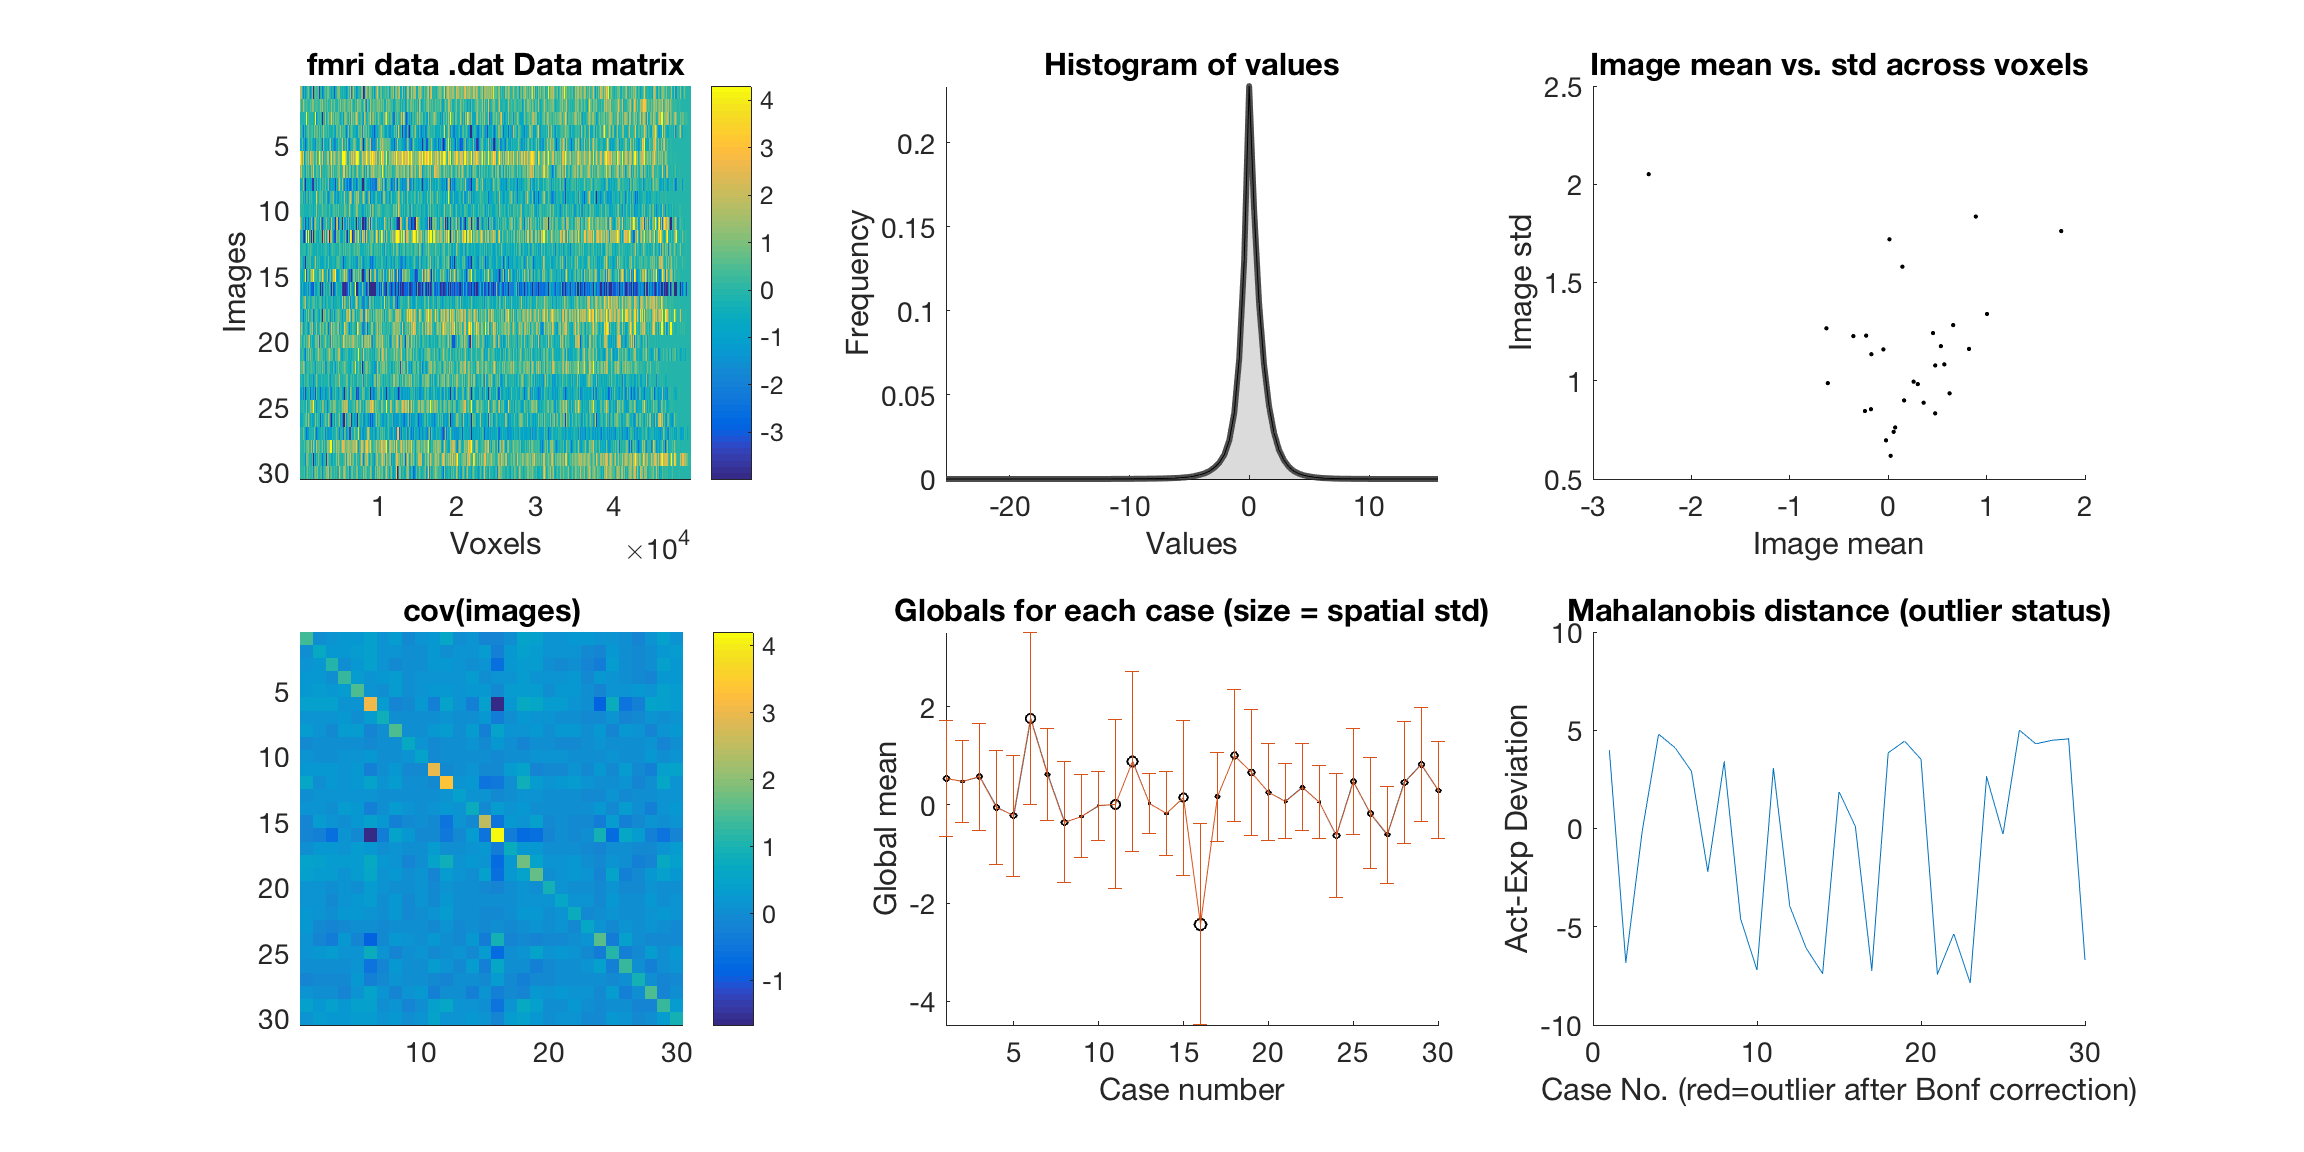

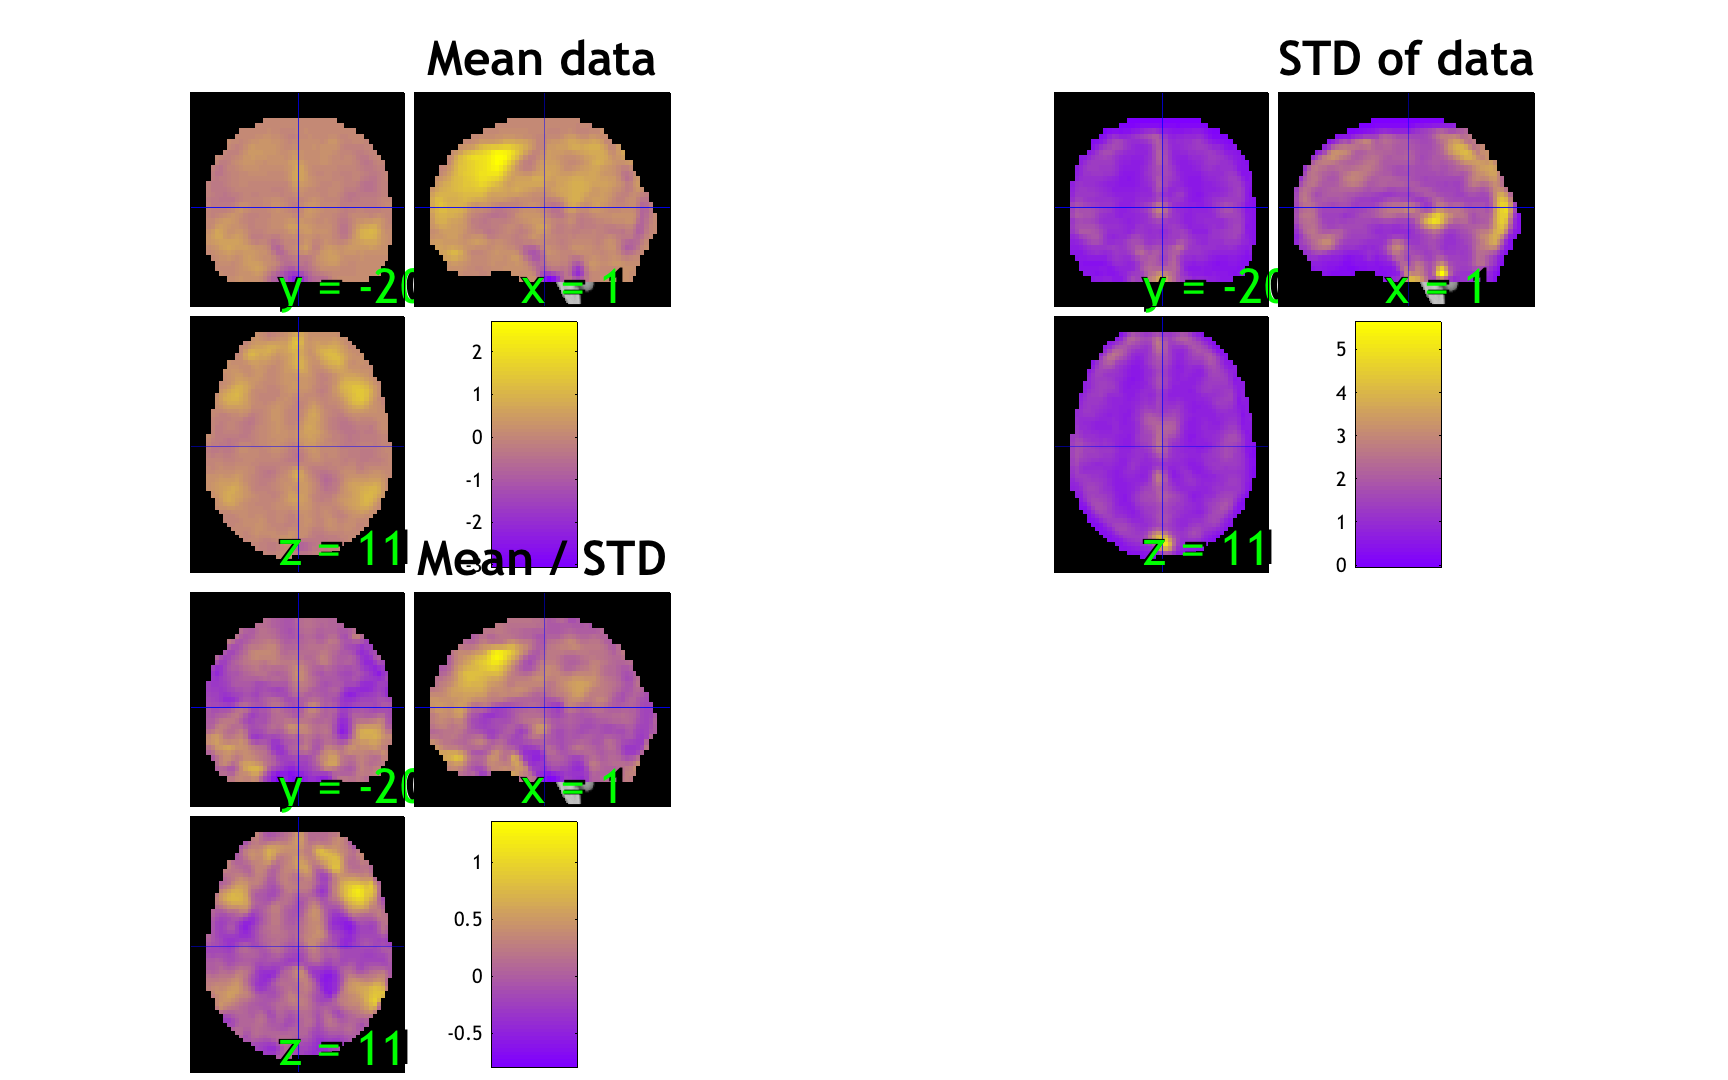

% This script uses object-oriented tools, which we cover in another tutorial. 
% For now, it's just a convenient way to get a set of image filenames.
% It creates plots of the dataset, but we will ignore those for now.
load_a_sample_dataset


% The active line of this script is:
% [data_obj, subject_names, image_names] = load_image_set('emotionreg');

% data_obj is an fmri_data object, with its own methods and properties
% We'll use the names

## Load the behavioral data and attach them to the data object


beh_data_file = which('Wager_2008_emotionreg_behavioral_data.txt')

beh_data_file = /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emotionreg_behavioral_data.txt

if isempty(beh_data_file), error('Sample behavioral data not found. '); end
beh = readtable(beh_data_file);

## Define the structure we need to save and run:

EXPT.subjects = subject_names;
EXPT.SNPM.P{1} = char(image_names{:}); % string matrix of images names
EXPT.SNPM.connums = 1;
EXPT.SNPM.connames = 'Reapp_vs_Look';
EXPT.mask = which('gray_matter_mask.img');
EXPT.cov = beh.Y_Reappraisal_Success;   

% Because we have one column in EXPT.cov, our 2nd-level design matrix 
% will contain two images (e.g., two t-maps/p-maps): 
% One for the intercept (always first) and one for the covariate entered.


## Create a directory for the results and go to it:

% This directory will contain subdirectories called robust00XX for each 
% Cell of images entered in EXPT.SNPM.P.
basedir = '/Users/tor/Documents/Code_Repositories/CANlab_help_examples/Robust_regression_walkthrough/Sample_analysis';

cd(basedir)

% Save the EXPT setup file for later reference:
save EXPT EXPT

Robfit.m
____________________________________________________________
Preparing covariates:
Cov   1: Centering and scaling to unit variance. Will be saved in rob_tmap_0002
____________________________________________________________
robfit: Will write to robust???? directories in: /Users/tor/Documents/Code_Repositories/CANlab_help_examples/Robust_regression_walkthrough/Sample_analysis
Robfit.m - working on Reapp_vs_Look
Running OLS and IRLS comparison (slower) - to turn this off, use 0 as 3rd input argument.
____________________________________________________________
No mask found. Analyzing all voxels.

Saving results in : robust0001 (Directory already exists. Will overwrite.)
Minimum allowed observations per voxel:26

Image name for first image:
 /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810001.img
Number of images:  30

 79790 voxels,  31 planes in analysis
	Done: 000%

000%

000%

000%001%

001%

001%

001%

001%

001%

001%

001%

002%

002%

002%

002%

002%002%

002%002%

003%003%

003%

003%

003%

003%

003%

003%

004%

004%

004%

004%

004%

004%

004%

004%005%

005%

005%

005%

005%

005%

005%

005%

006%

006%

006%

006%

006%

006%

006%

006%

007%

007%

007%

007%

007%

007%

007%

007%

008%

008%

008%

008%

008%

008%008%

008%009%

009%

009%

009%

009%

009%

009%

009%

010%

010%

010%010%

010%

010%

010%

010%

011%

011%011%011%

011%

011%

011%011%012%012%

012%012%

012%012%

012%012%

013%

013%013%

013%

013%

013%

013%

013%

014%

014%

014%

014%

014%

014%014%

014%

015%

015%

015%

015%

015%015%

015%

015%

016%

016%

016%

016%

016%016%

016%

016%

017%

017%

017%

017%

017%

017%

017%

017%

018%

018%

018%

018%

018%

018%

018%

018%019%

019%

019%019%

019%

019%019%

019%020%

020%020%

020%020%

020%020%

020%

021%

021%

021%

021%021%

021%

021%

021%022%

022%

022%

022%

022%

022%022%

022%023%023%

023%

023%

023%

023%

023%

023%

024%024%

024%

024%

024%

024%

024%

024%

025%

025%

025%

025%025%025%

025%

025%

026%

026%

026%

026%

026%

026%

026%

026%

027%

027%

027%027%

027%

027%

027%027%

028%028%

028%

028%

028%028%

028%

028%

029%

029%

029%

029%029%

029%

029%

029%

030%

030%

030%

030%

030%030%030%030%031%

031%

031%

031%

031%031%031%

031%

032%

032%

032%032%

032%032%

032%

032%

033%

033%

033%

033%

033%

033%

033%

033%

034%

034%

034%

034%

034%034%

034%

034%035%

035%035%035%

035%

035%

035%

035%

036%

036%

036%036%

036%036%

036%

036%

037%

037%

037%

037%037%

037%

037%

037%

038%038%

038%

038%

038%

038%

038%

038%

039%

039%

039%

039%

039%

039%039%039%

040%040%

040%

040%040%

040%

040%

040%

041%

041%

041%

041%

041%

041%

041%

041%

042%

042%

042%

042%

042%

042%

042%

042%043%

043%

043%

043%

043%

043%

043%

043%

044%

044%

044%

044%

044%

044%

044%

044%

045%

045%

045%

045%

045%

045%

045%

045%

046%

046%

046%

046%

046%046%

046%046%

047%

047%047%047%

047%047%

047%047%

048%

048%

048%

048%

048%

048%

048%

049%049%049%

049%

049%

049%

049%

049%

050%

050%

050%

050%

050%

050%050%050%051%

051%

051%

051%

051%

051%

051%

051%

052%052%

052%

052%

052%

052%

052%

052%

053%

053%

053%

053%

053%

053%

053%

053%054%

054%054%

054%

054%

054%

054%

054%

055%

055%055%055%

055%

055%

055%

055%

056%

056%

056%

056%

056%

056%

056%

056%057%057%

057%

057%

057%

057%

057%

057%

058%

058%

058%

058%

058%

058%

058%

058%

059%

059%

059%059%

059%

059%

059%

059%

060%060%

060%060%

060%

060%

060%060%

061%

061%

061%

061%

061%061%

061%

061%062%

062%062%

062%

062%

062%

062%

062%063%

063%

063%

063%

063%

063%063%

063%

064%

064%064%

064%

064%

064%

064%

064%

065%

065%

065%

065%

065%

065%

065%

065%

066%

066%

066%

066%066%

066%066%066%

067%

067%

067%

067%

067%

067%

067%067%

068%

068%068%

068%

068%

068%

068%

068%

069%

069%

069%

069%

069%069%069%

069%

070%070%

070%

070%

070%

070%

070%

070%

071%

071%

071%

071%

071%

071%071%

071%

072%

072%

072%

072%

072%

072%

072%

072%

073%

073%

073%073%

073%

073%073%

073%

074%

074%

074%

074%

074%

074%

074%

074%

075%

075%

075%

075%

075%

075%

075%

075%

076%

076%

076%

076%

076%

076%

076%076%

077%077%

077%

077%

077%

077%

077%

077%

078%078%

078%

078%

078%

078%

078%

078%

079%

079%

079%079%

079%

079%079%079%080%

080%

080%

080%

080%

080%

080%

080%

081%

081%

081%

081%

081%081%

081%

081%

082%

082%

082%

082%

082%

082%

082%

082%

083%

083%083%

083%083%

083%

083%

083%

084%

084%

084%

084%

084%

084%

084%

084%

085%

085%

085%

085%

085%

085%

085%

085%

086%

086%

086%

086%

086%

086%

086%

086%

087%

087%

087%

087%

087%

087%

087%

087%

088%

088%

088%

088%

088%

088%

088%

088%

089%

089%

089%

089%

089%

089%

089%

089%

090%

090%

090%

090%

090%

090%

090%

090%

091%

091%

091%

091%

091%

091%

091%

091%

092%

092%

092%

092%

092%092%

092%

092%

093%

093%

093%

093%

093%

093%

093%

093%

094%

094%

094%

094%

094%

094%

094%

094%

095%

095%

095%

095%

095%

095%

095%

096%

096%

096%

096%

096%

096%

096%

096%

097%

097%

097%

097%

097%

097%

097%

097%098%098%

098%

098%

098%

098%

098%098%

099%

099%

099%

099%

099%

099%

099%

099%

100%

100%

100%100%

 done. 	writing volumes.


Error using robfit>rob_fit (line 453)
Unknown SPM version "SPM12": neuroscientists of the future, fix me!

Error in robfit (line 175)
        [EXPT.SNPM.rob_betas{i},EXPT.SNPM.ols_betas{i}] = rob_fit(EXPT.SNPM.P{i}, covt, EXPT.SNPM.connums(i), dools, domask, EXPT.SNPM.connames(i,:), basedir);

EXPT = robfit(EXPT);

% Try help robfit for more options.

% e.g., you can specify that you want to run only some of the contrasts 
% in EXPT.SNPM.P.  You can specify that you want to create OLS images 
% side by side with robust images to compare.  
% And you can specify a mask filename.  
% The mask image should contain 1’s and 0’s, with 1’s in voxels you want to analyze.


## Get batch results

Grouping contiguous voxels:   1 regions
Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.
axial montage: 21561 voxels displayed, 28231 not displayed on these slices
sagittal montage: 1434 voxels displayed, 48358 not displayed on these slices


axial montage: 21561 voxels displayed, 28231 not displayed on these slices


sagittal montage: 1434 voxels displayed, 48358 not displayed on these slices


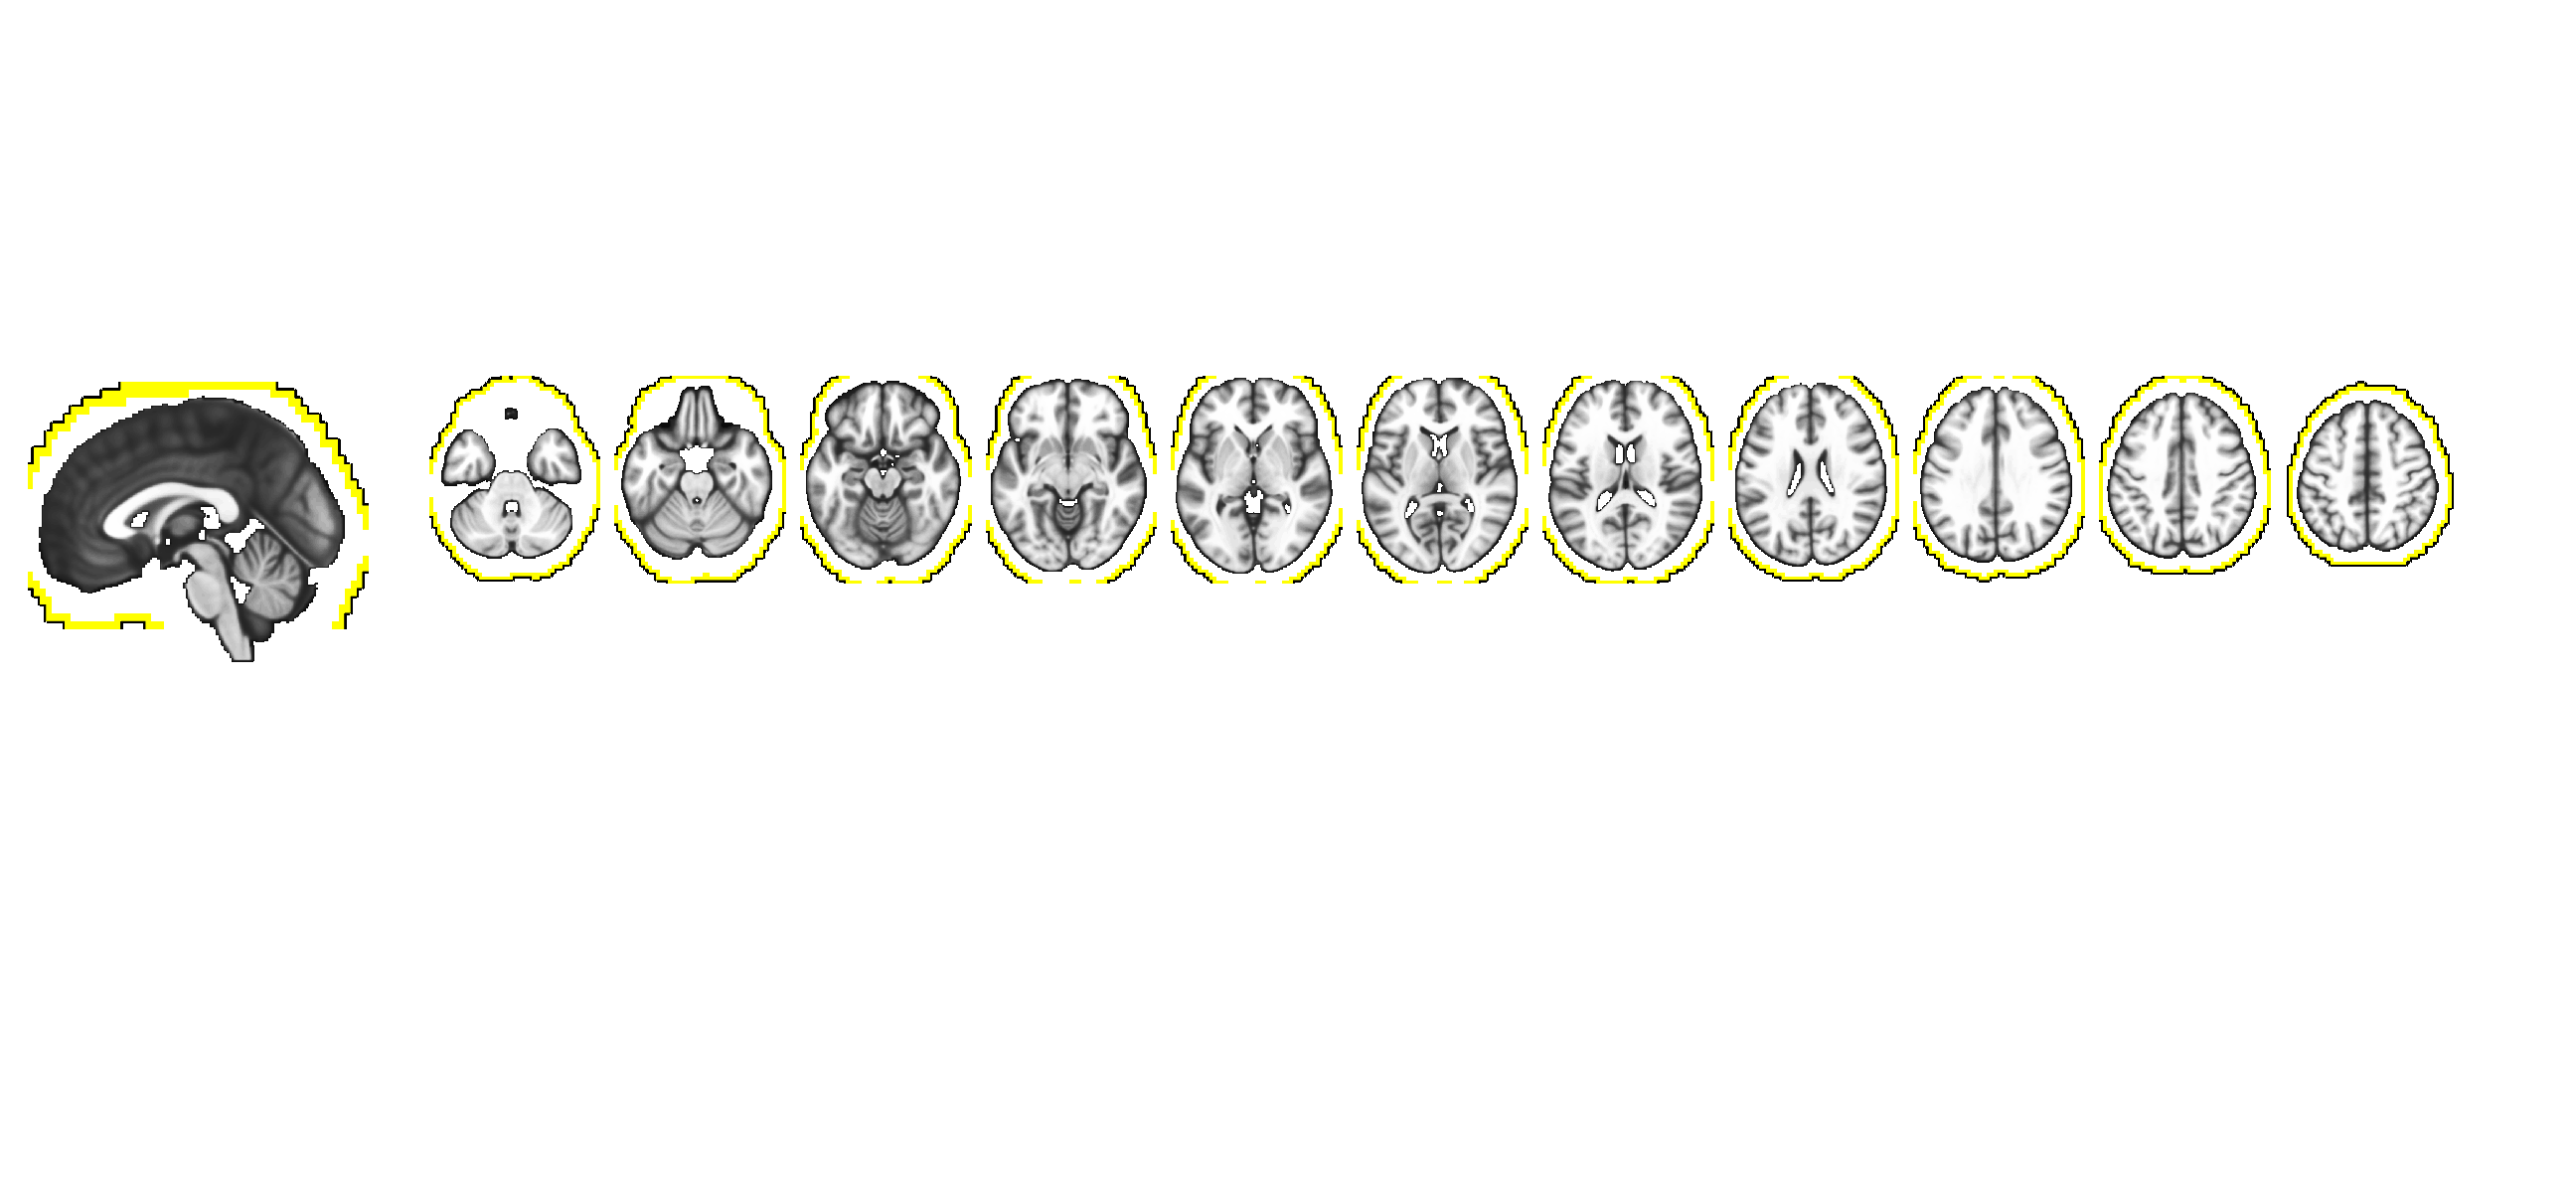


SPM12: spm_check_registration (v6245)              18:03:59 - 04/04/2017
Display /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans =     [1×1 struct]


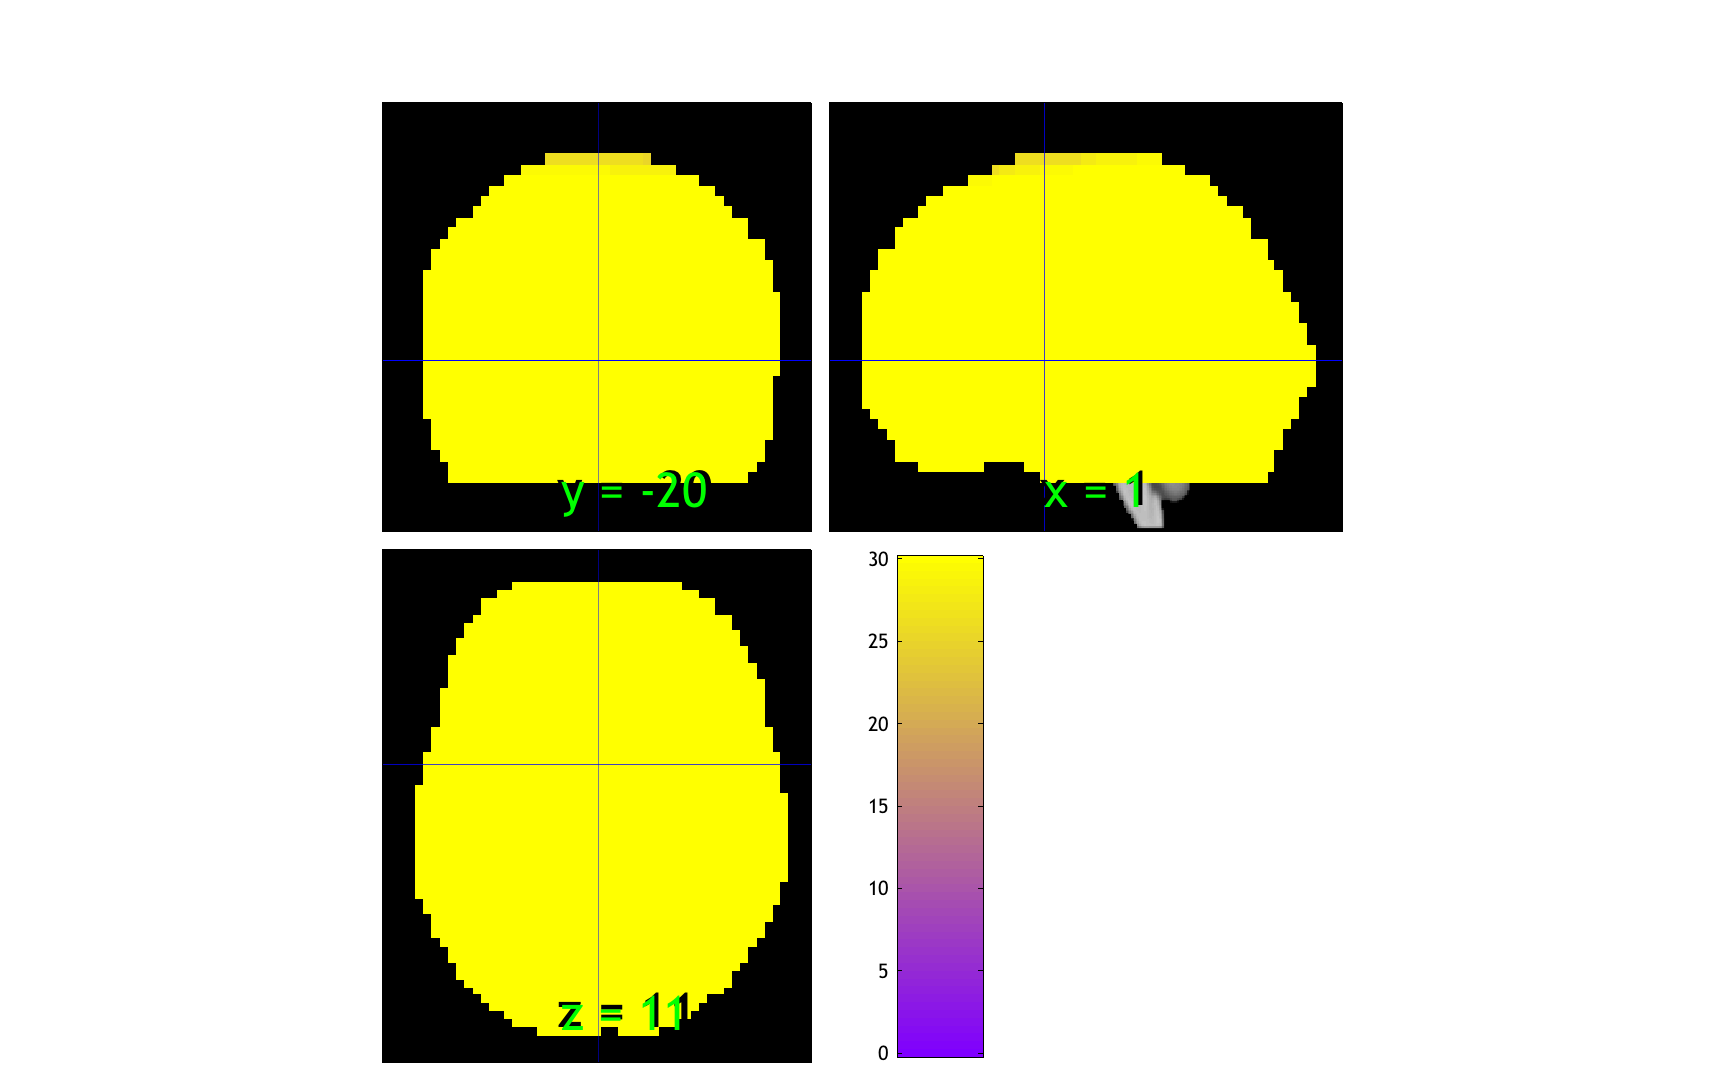

% Go to the robust regression folder and run the batch script:

cd(basedir)

ans = No intercept detected, adding intercept to last column of design matrix

regression > Y: 49792 voxels. X:   2 obs, 
Predicting Brain Activity from dat.X
Running in OLS Mode
Model run in 0 minutes and 0.06 seconds

Image   1
Positive effect: 9098 voxels, min p-value: 0.00001192
Negative effect: 188 voxels, min p-value: 0.00170541

Image   2
Positive effect: 955 voxels, min p-value: 0.00012028
Negative effect: 3775 voxels, min p-value: 0.00005484


Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.


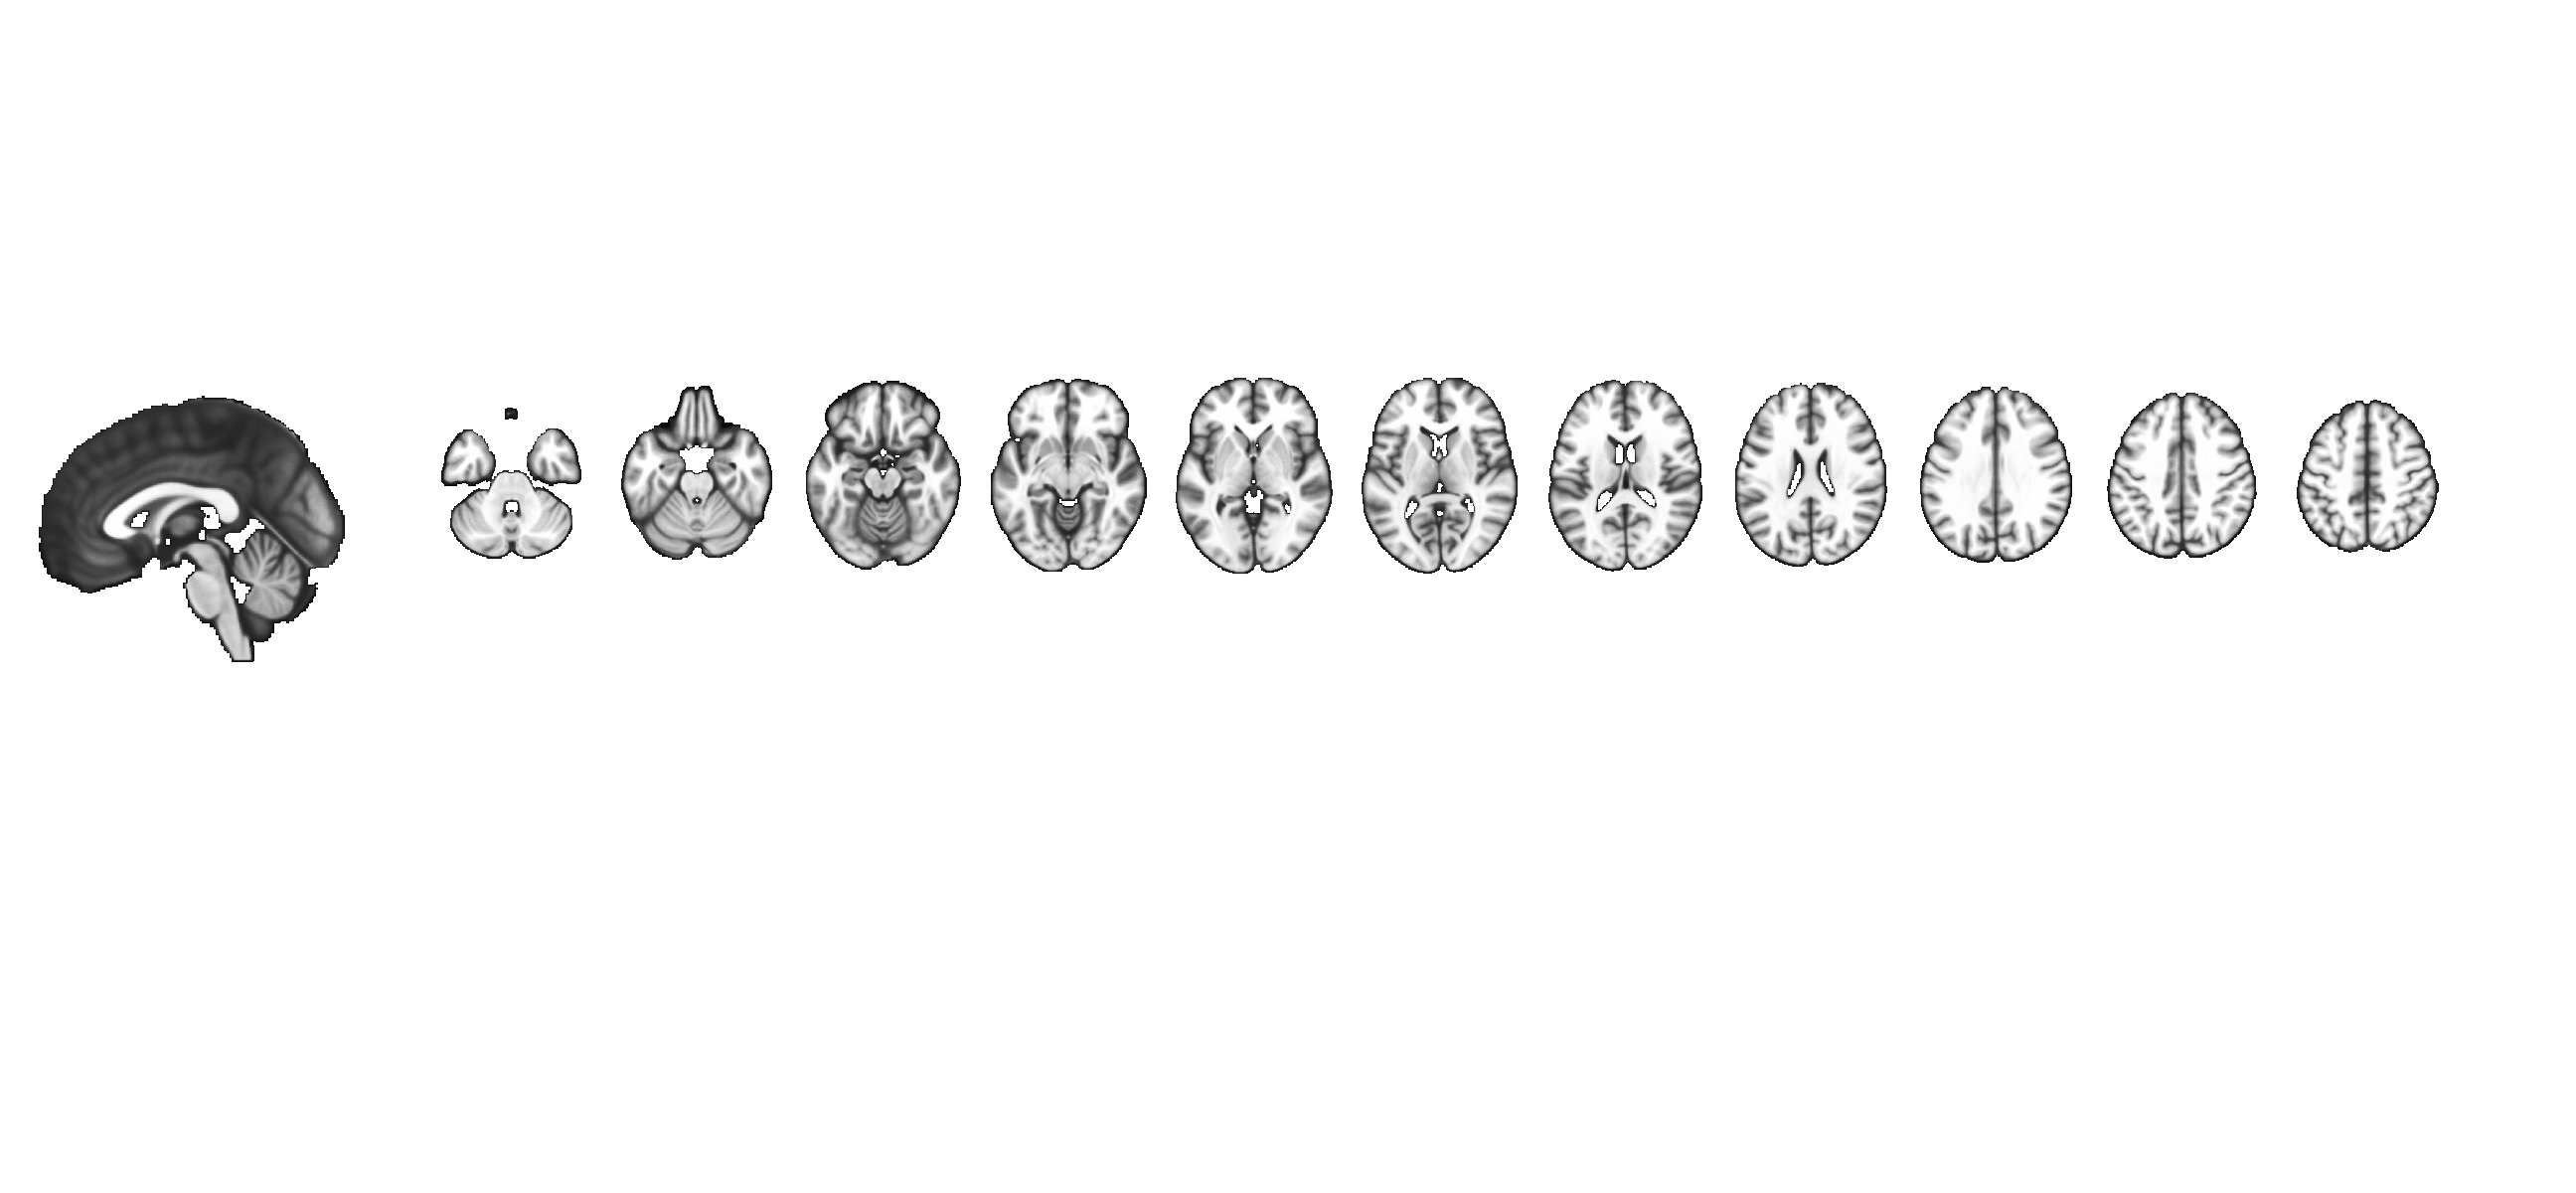

Grouping contiguous voxels:  62 regions


axial montage: 3956 voxels displayed, 5330 not displayed on these slices
sagittal montage: 486 voxels displayed, 8800 not displayed on these slices


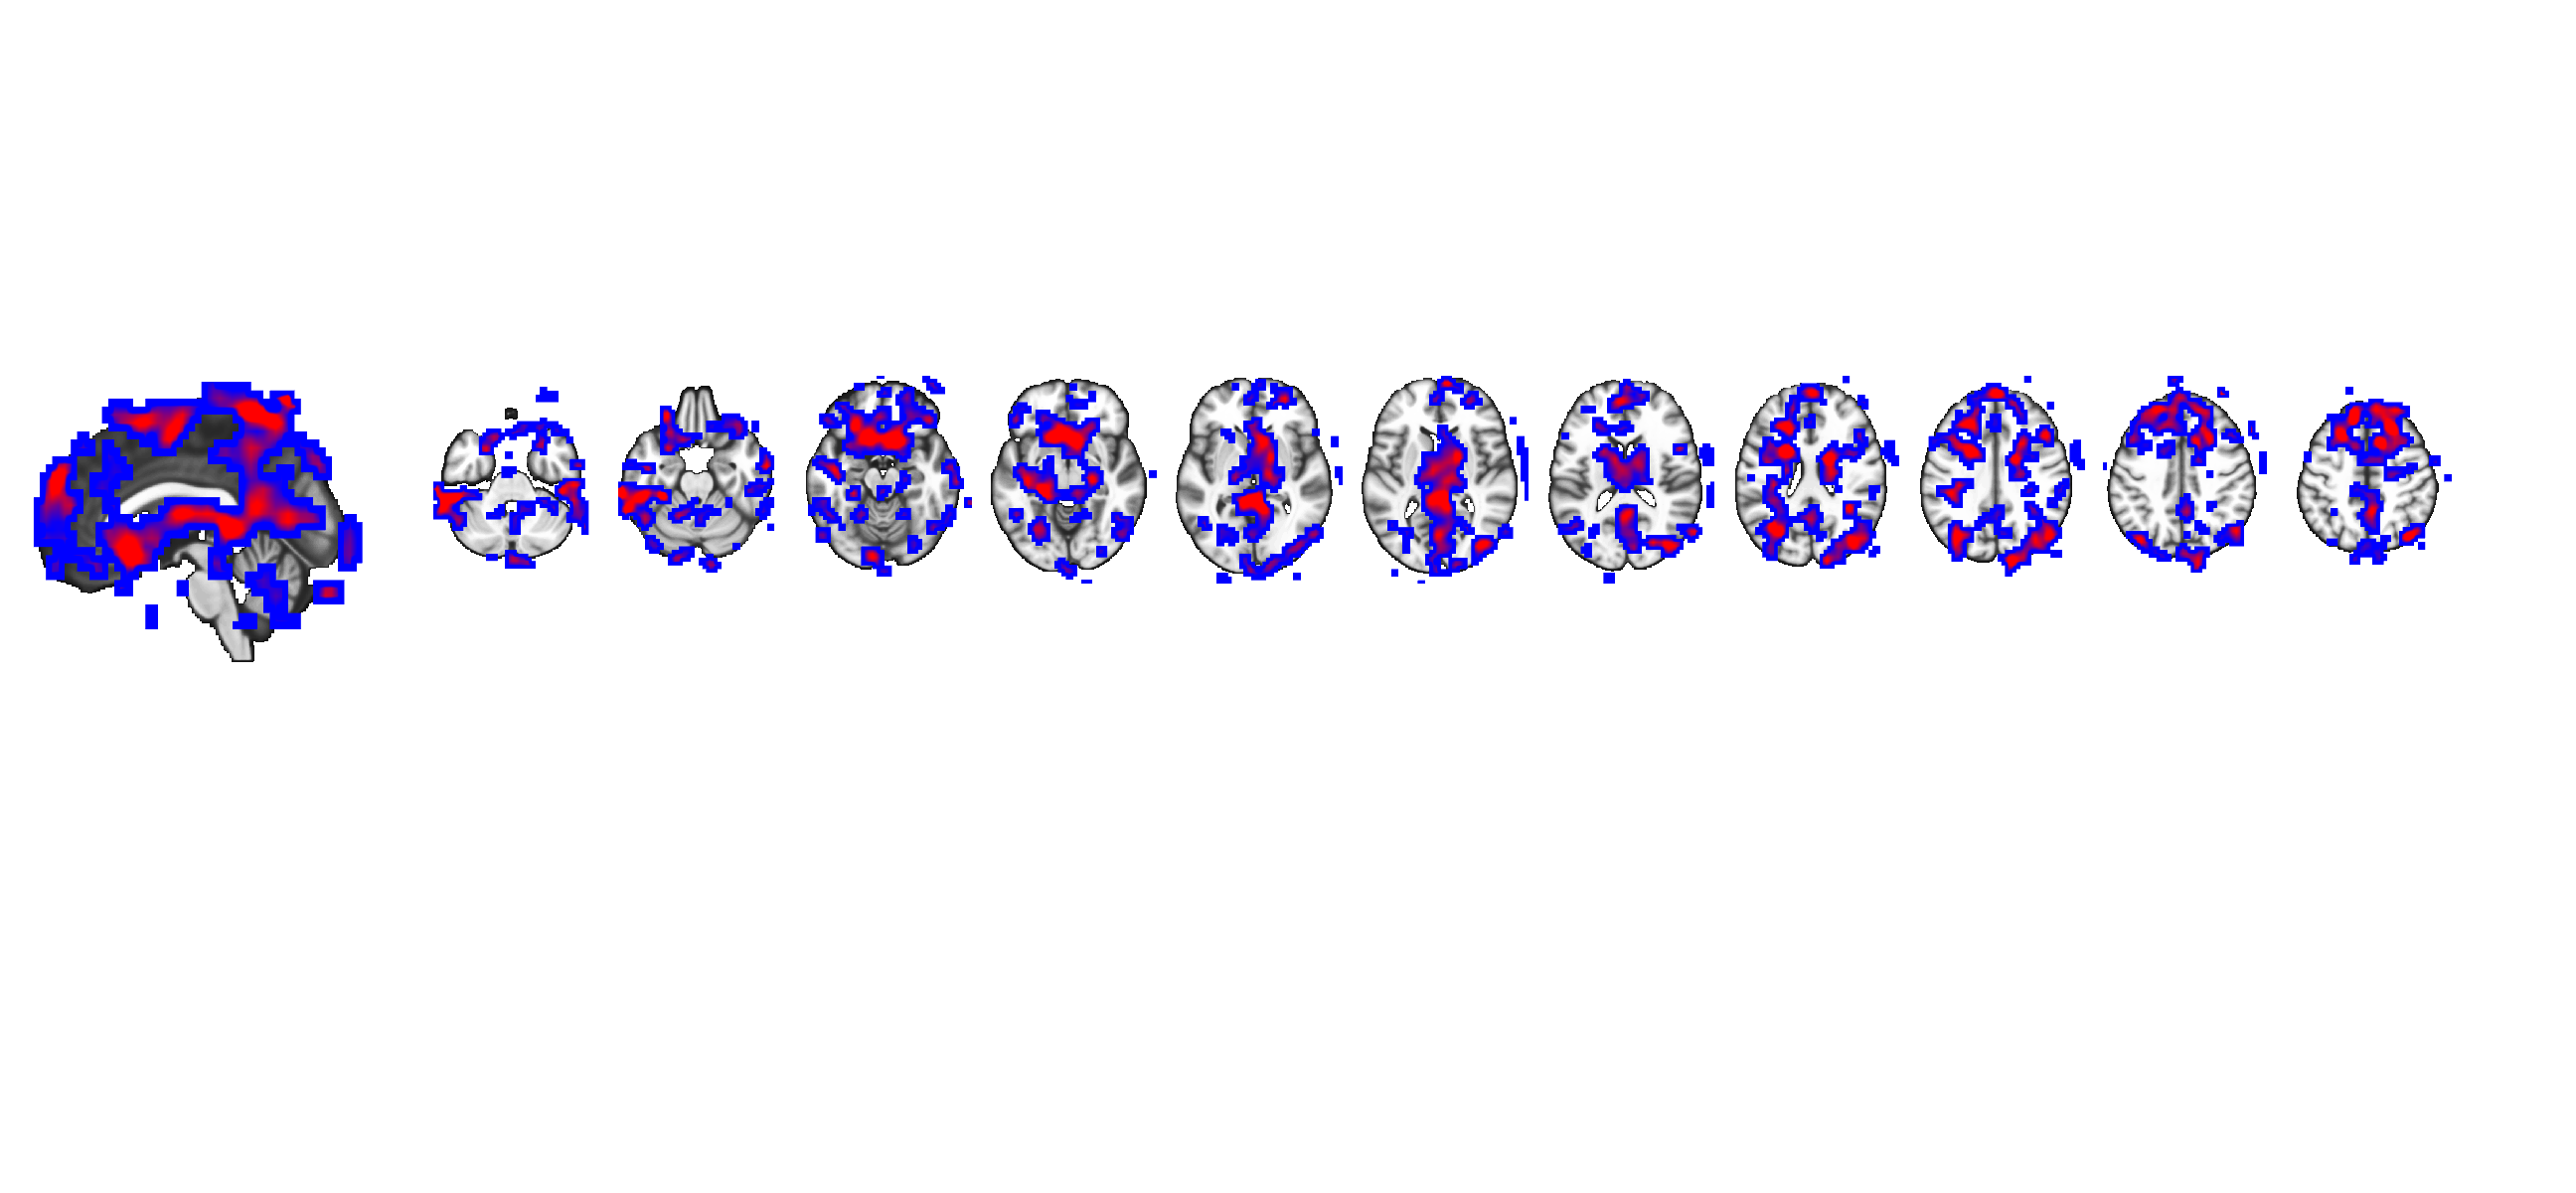

mask = /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/gray_matter_mask.img

Using default mask: /Users/tor/Documents/Code_External/spm12/toolbox/FieldMap/brainmask.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1409312 bytes
Loading image number:     0    1
Elapsed time is 0.029468 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.



Image   1
Positive effect: 962 voxels, min p-value: 0.00002897
Negative effect:   0 voxels, min p-value: 0.00847960


Grouping contiguous voxels:  52 regions
axial montage: 358 voxels displayed, 604 not displayed on these slices
sagittal montage:  56 voxels displayed, 906 not displayed on these slices


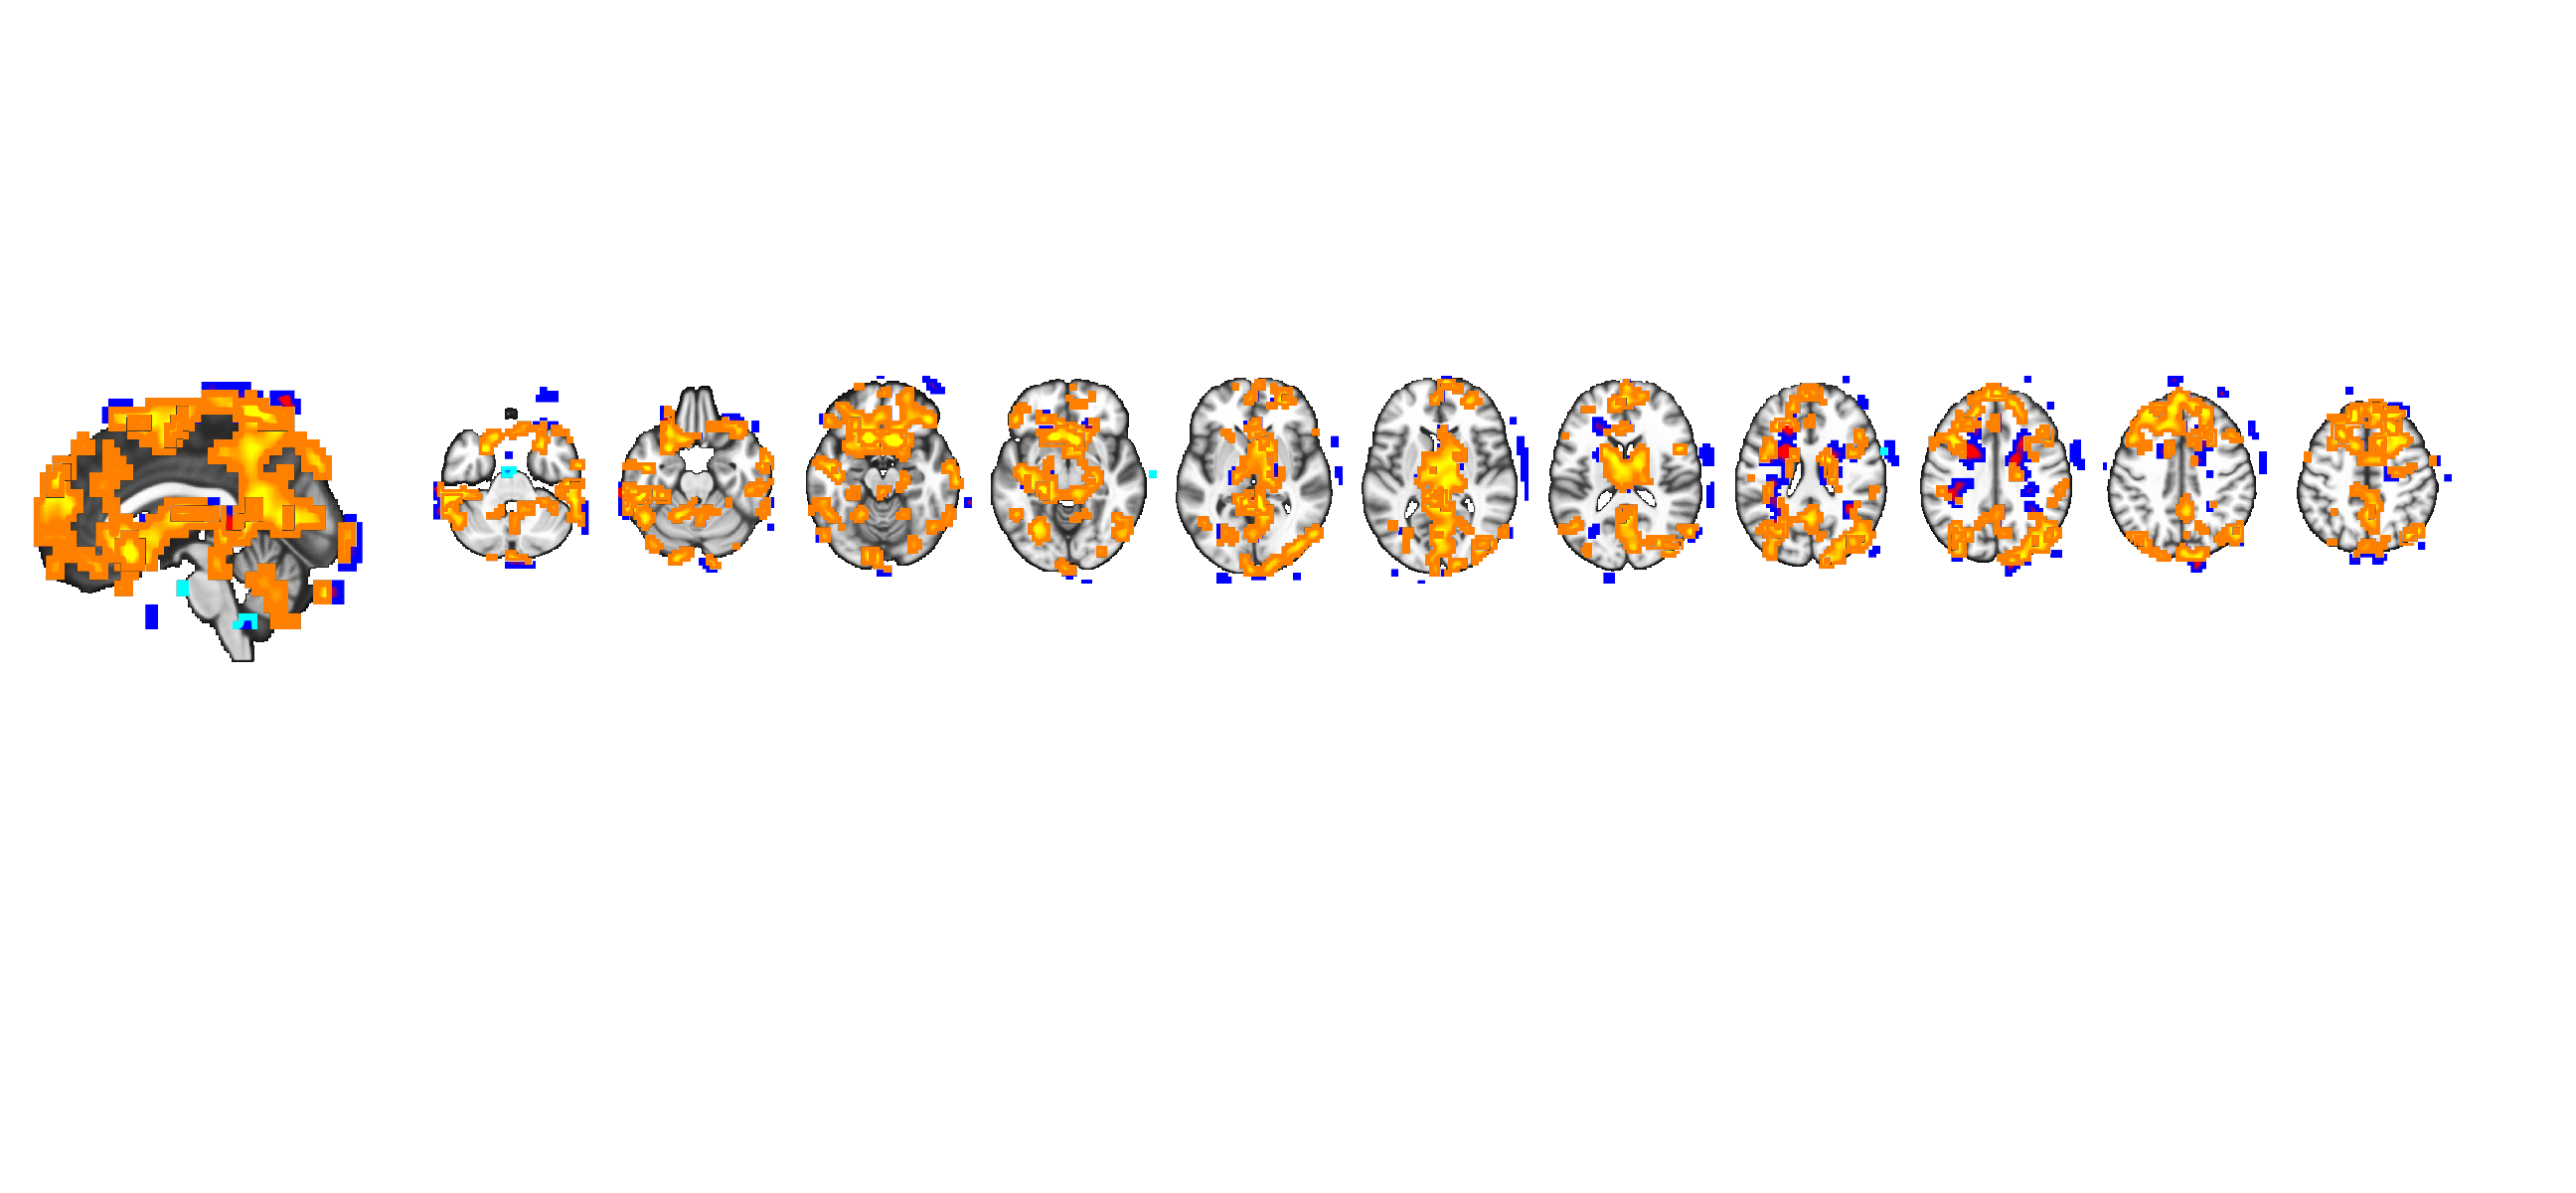

cd('robust0001')

robust_results_batch('mask', EXPT.mask, 'thresh', [.001 .005 .05], 'size', [5 1 1], 'prune');

% You can edit this script or see ROBUST_REGRESSION_HELP.docx
% For more options on how to use display and results functions

## Robust regression:

• Outliers can violate assumptions, have very large effects on regression coefficients

• High-variance observations tend to dominate if their observed values are extreme

• When assumptions cannot be checked at each voxel, automatic procedures for weighting based on outlier status advantageous

• Robust regression: Automatic procedure for identifying cases that are potential outliers and down-weighting

• Iterative GLS, estimation procedure, but weights are based on residual value rather than variancePotential way to deal with heteroscedastic variances

ans = No intercept detected, adding intercept to last column of design matrix

regression > Y: 49792 voxels. X:   2 obs, 
Predicting Brain Activity from dat.X
Running in Robust Mode


Model run in 1 minutes and 30.18 seconds

Image   1
Positive effect: 7056 voxels, min p-value: 0.00000000
Negative effect: 486 voxels, min p-value: 0.00002585

Image   2
Positive effect: 1721 voxels, min p-value: 0.00000120
Negative effect: 3251 voxels, min p-value: 0.00000002


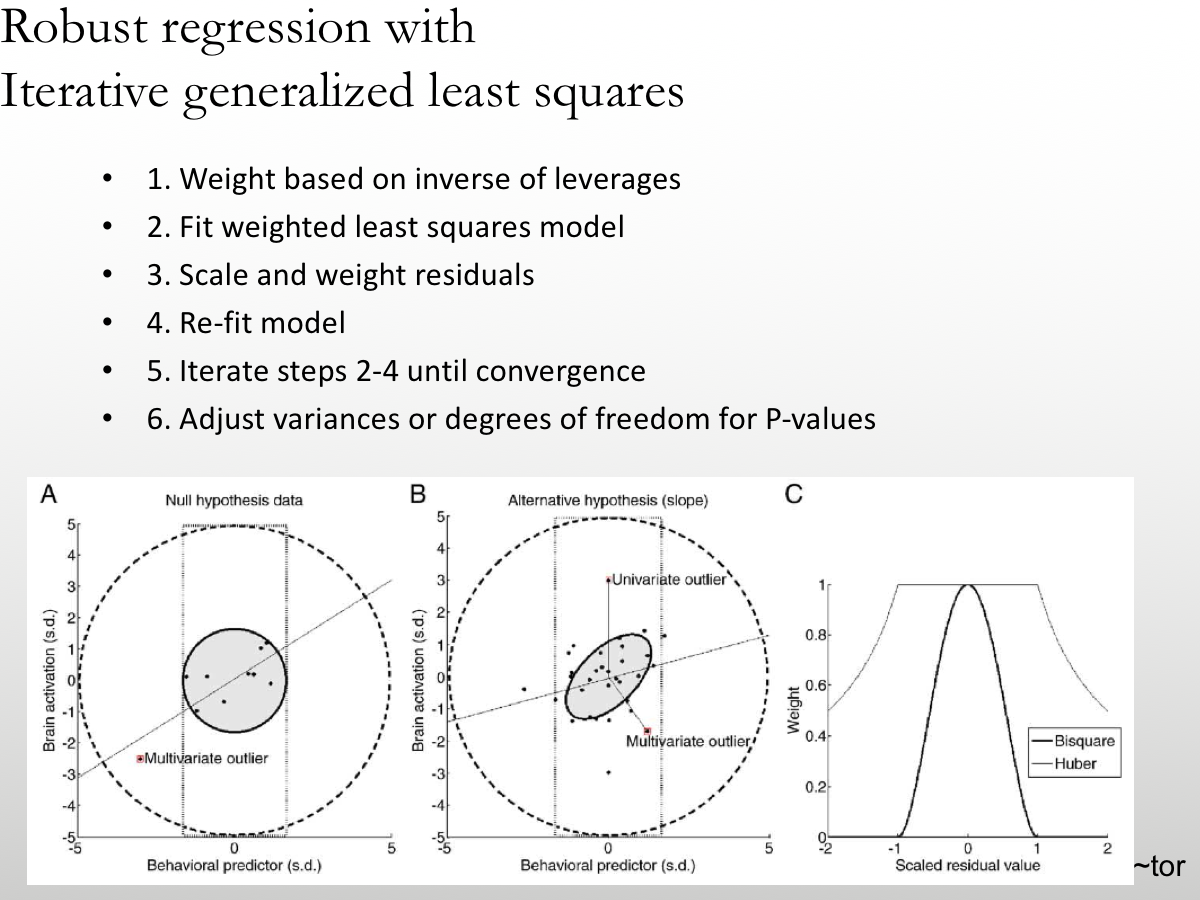

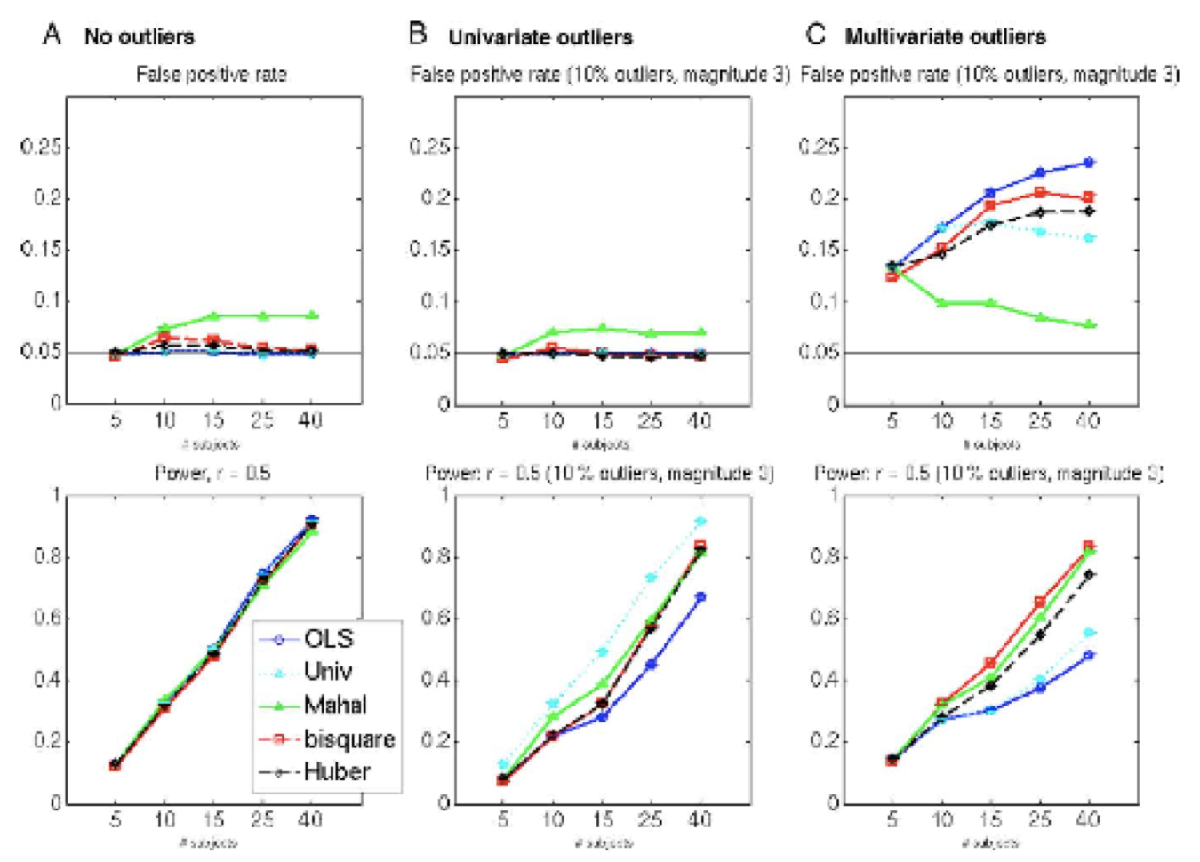

Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.



Image   1
Positive effect: 1311 voxels, min p-value: 0.00000000
Negative effect:  67 voxels, min p-value: 0.00002585

Image   2
Positive effect: 279 voxels, min p-value: 0.00000120
Negative effect: 623 voxels, min p-value: 0.00000002


Grouping contiguous voxels: 123 regions
axial montage: 710 voxels displayed, 668 not displayed on these slices
sagittal montage: 100 voxels displayed, 1278 not displayed on these slices


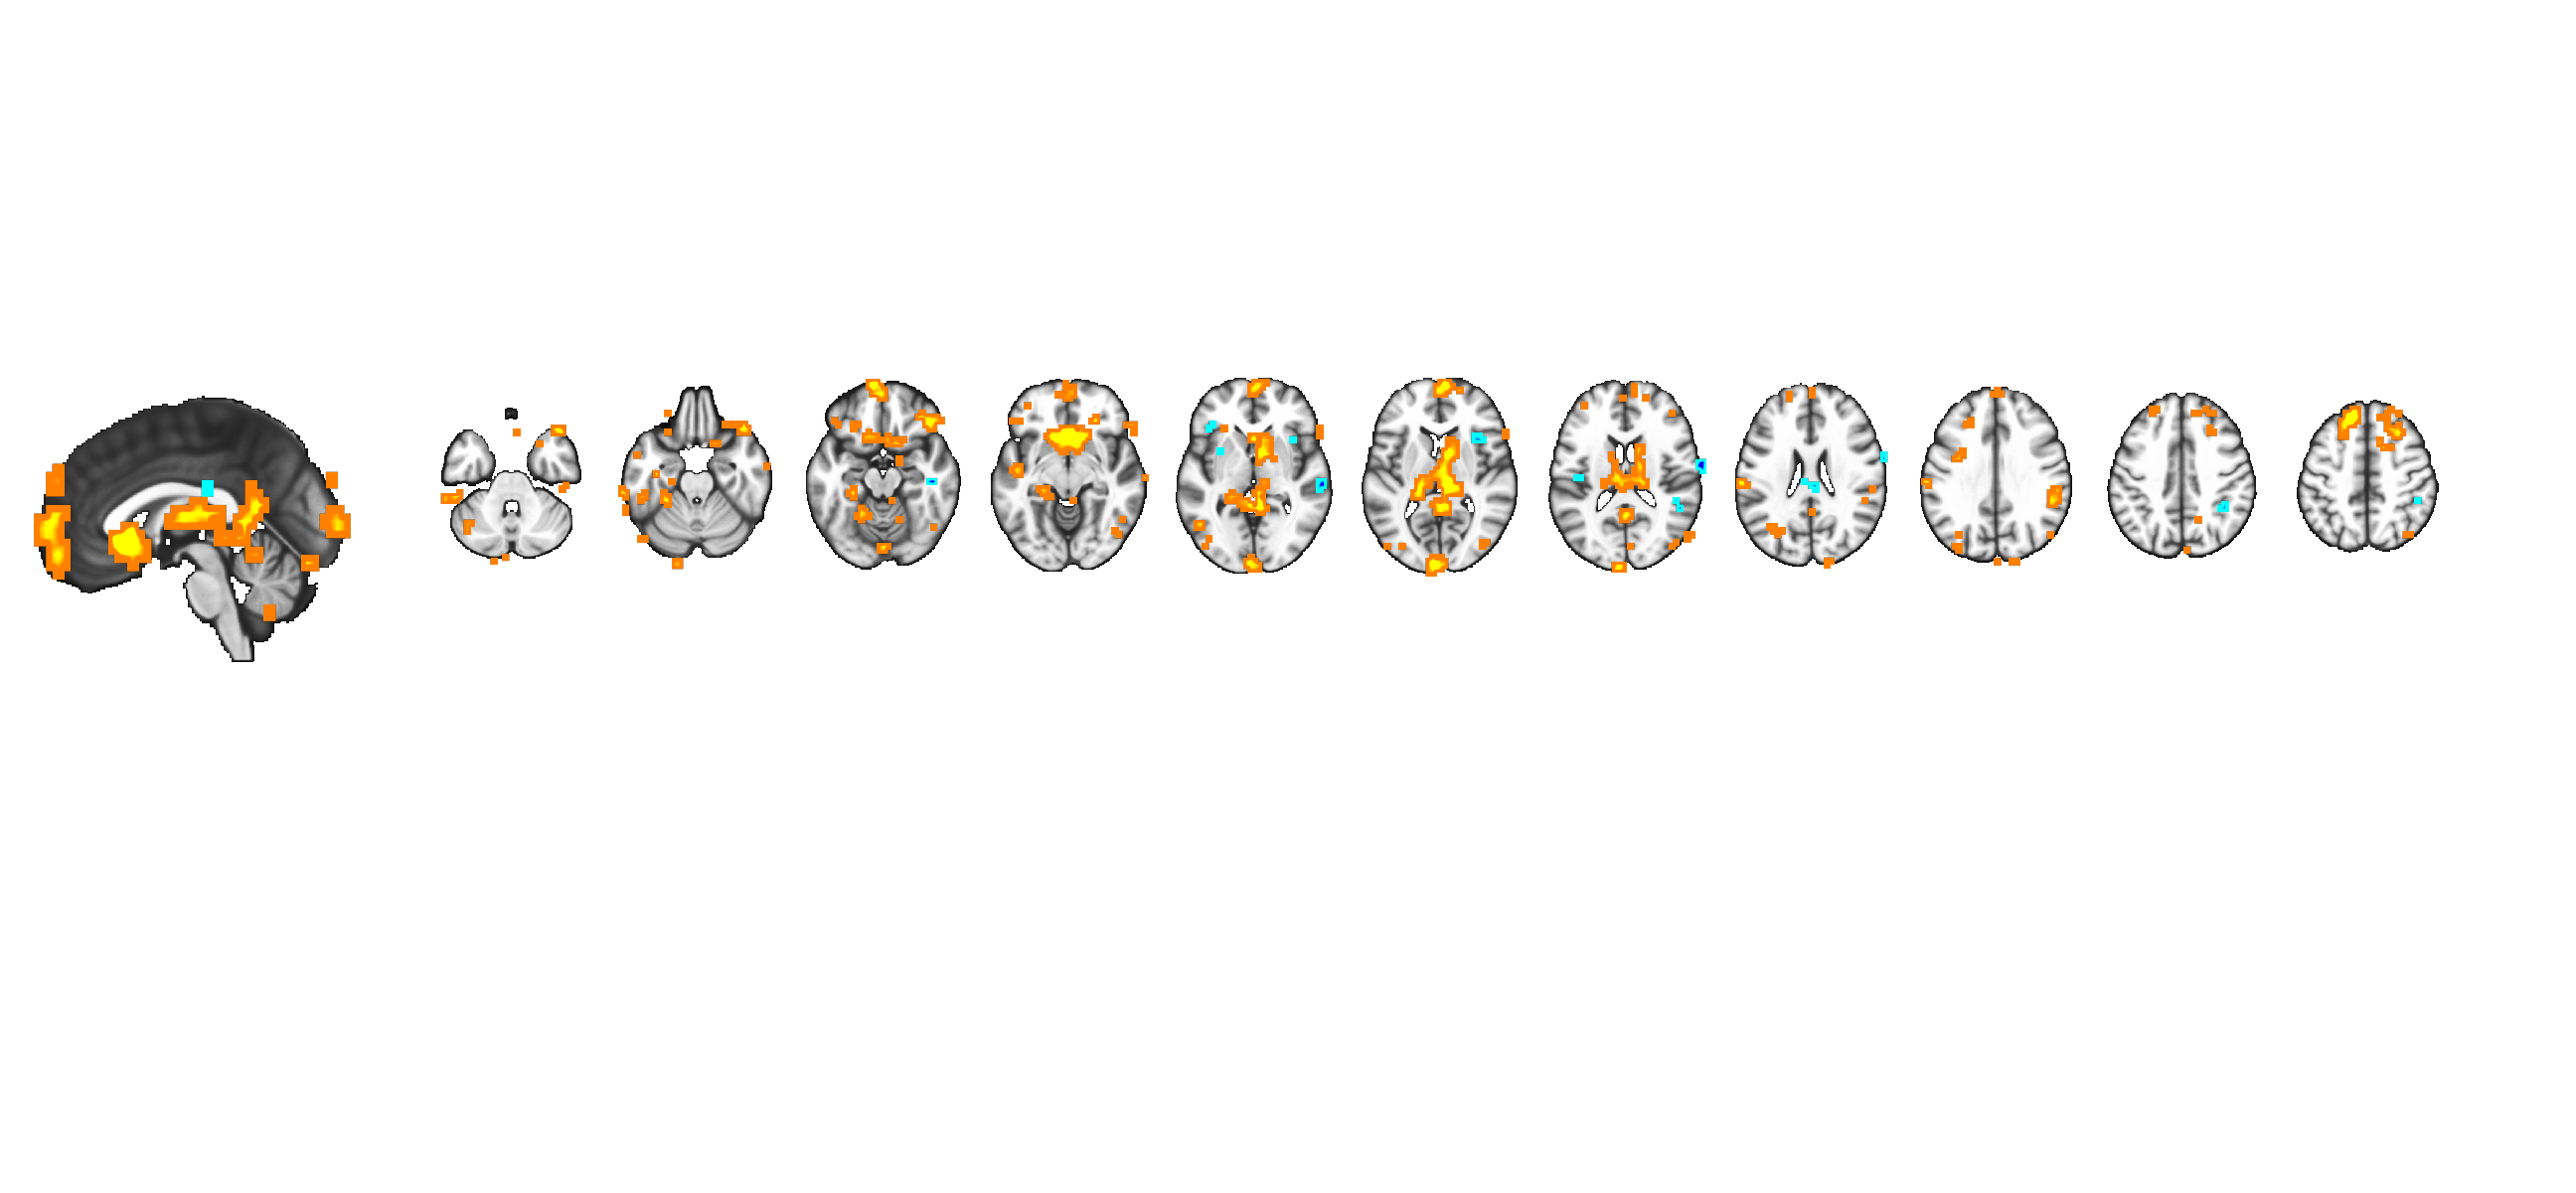

Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.


Image   1 FDR q < 0.050 threshold is 0.000472

Image   1
Positive effect: 314 voxels, min p-value: 0.00000000
Negative effect:  10 voxels, min p-value: 0.00002585
Image   2 FDR q < 0.050 threshold is 0.000073

Image   2
Positive effect:  23 voxels, min p-value: 0.00000120
Negative effect:  51 voxels, min p-value: 0.00000002


Grouping contiguous voxels:  48 regions
axial montage: 169 voxels displayed, 155 not displayed on these slices
sagittal montage:  35 voxels displayed, 289 not displayed on these slices


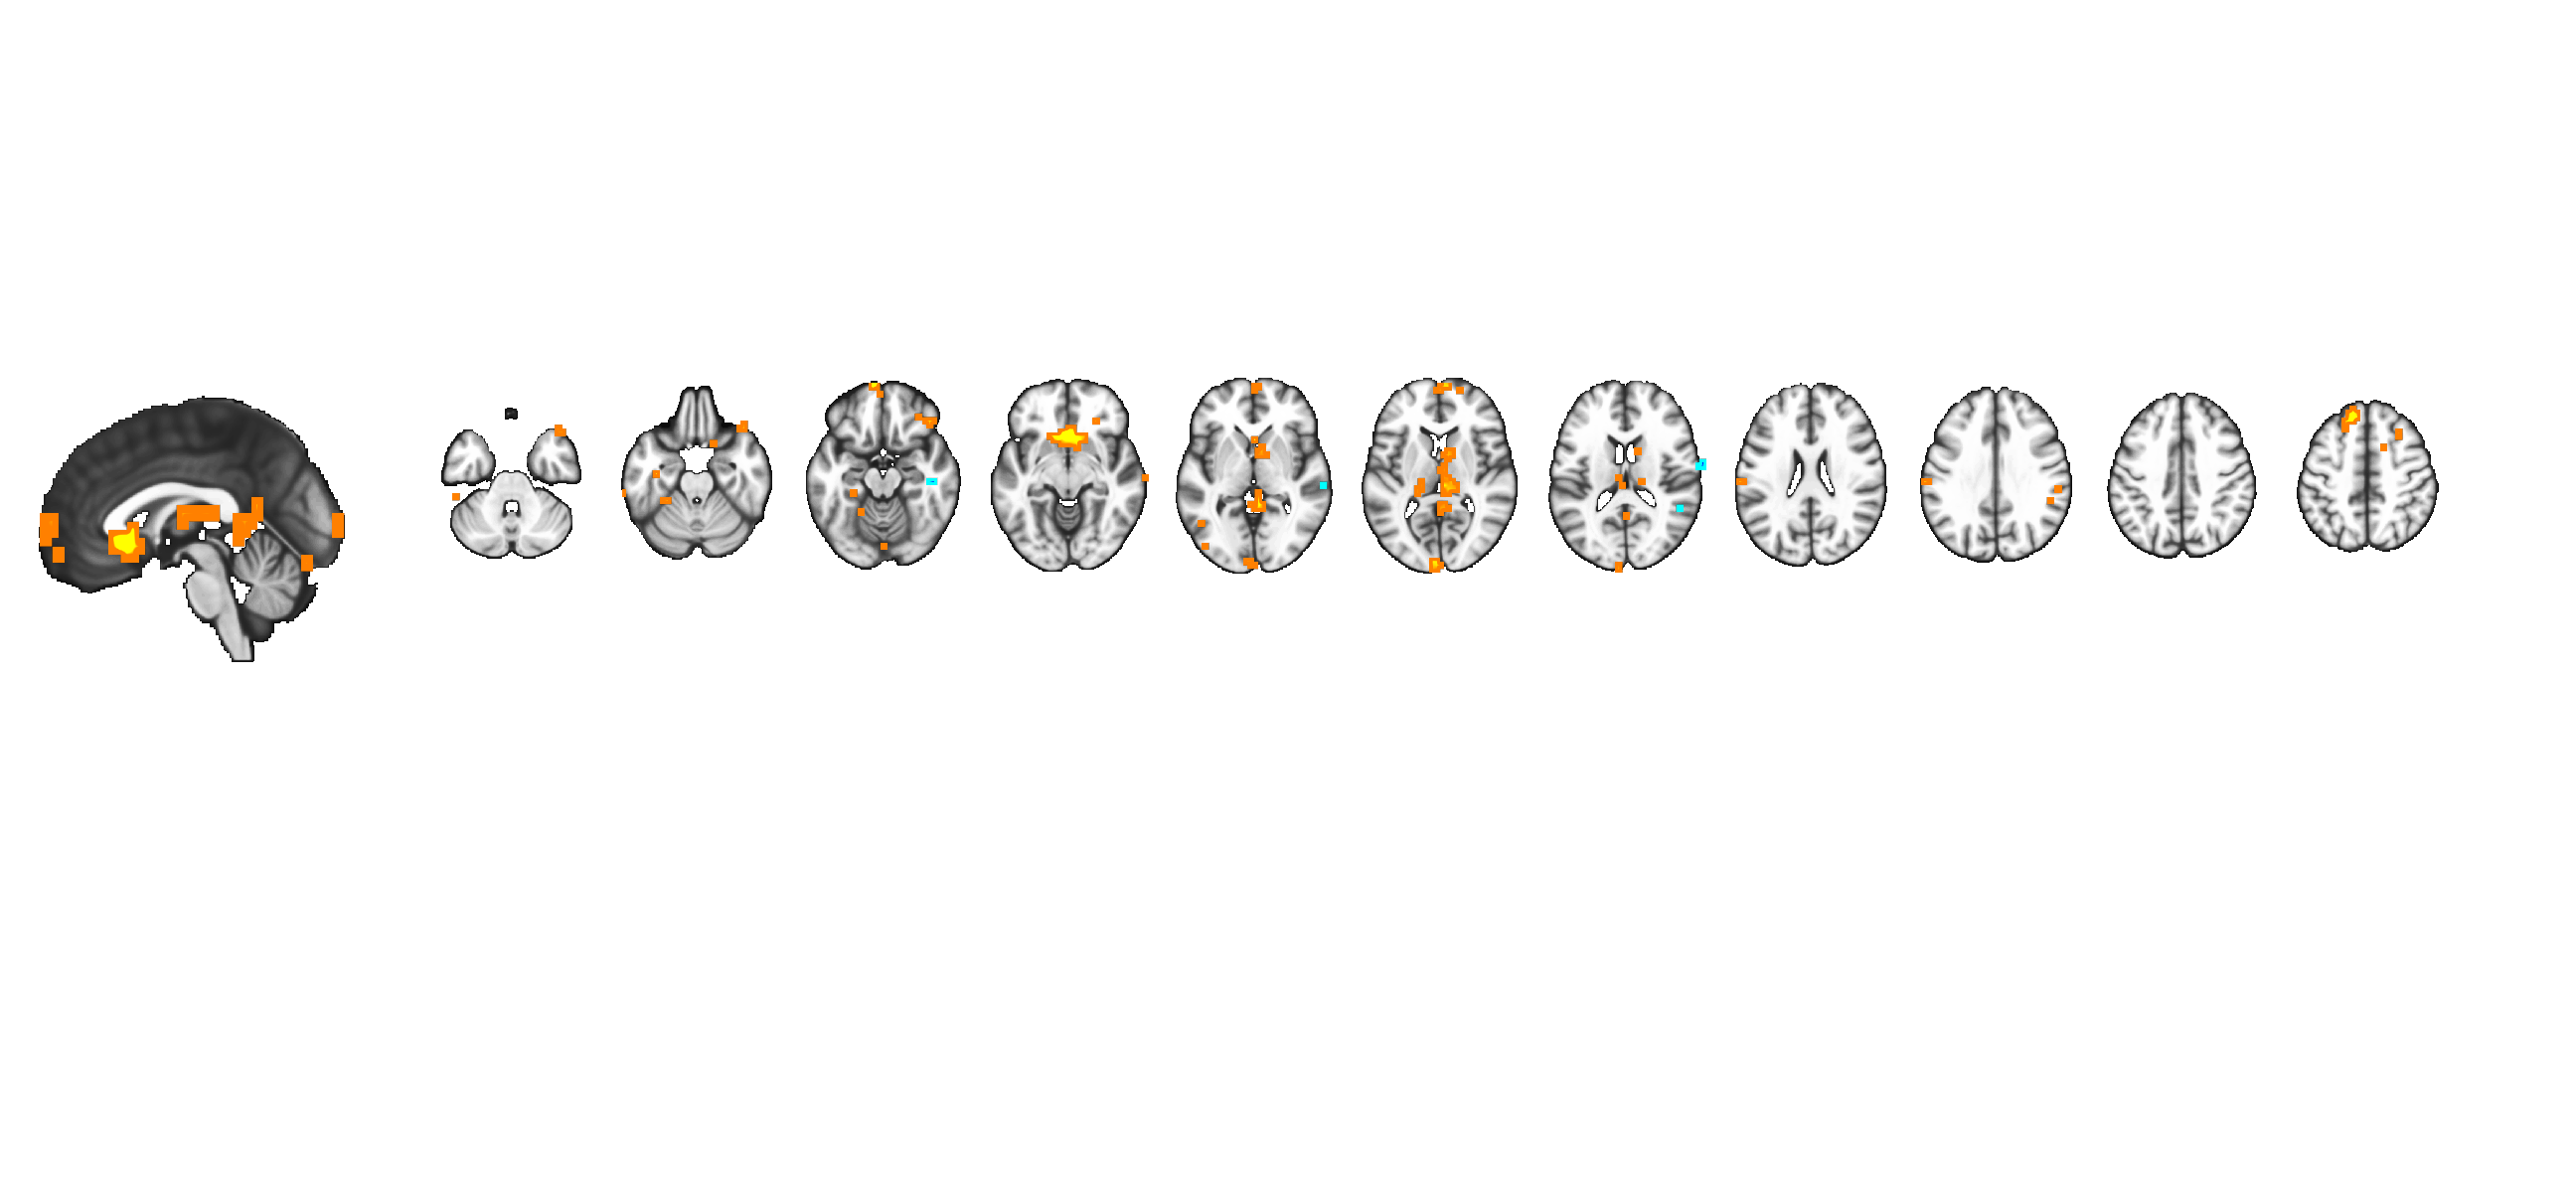

fmri_data.extract_roi_averages: Defining mask object. 
Grouping contiguous voxels: 123 regions
Averaging data. Done.



SPM12: spm_check_registration (v6245)              18:38:31 - 04/04/2017
Display /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


    region_num      colorsmatrix   
    __________    _________________

     1              1      0      0
     2              0      1      0
     3              0      0      1
     4              1      1      0
     5              1      0      1
     6              0      1      1
     7              1    0.5      0
     8            0.5      1      0
     9            0.5      0      1
    10              1      0    0.5
    11              0      1    0.5
    12              0    0.5      1
    13            0.5      0      0
    14              0    0.5      0
    15              0      0    0.5
    16            0.5    0.5      0
    17            0.5      0    0.5
    18              0    0.5    0.5



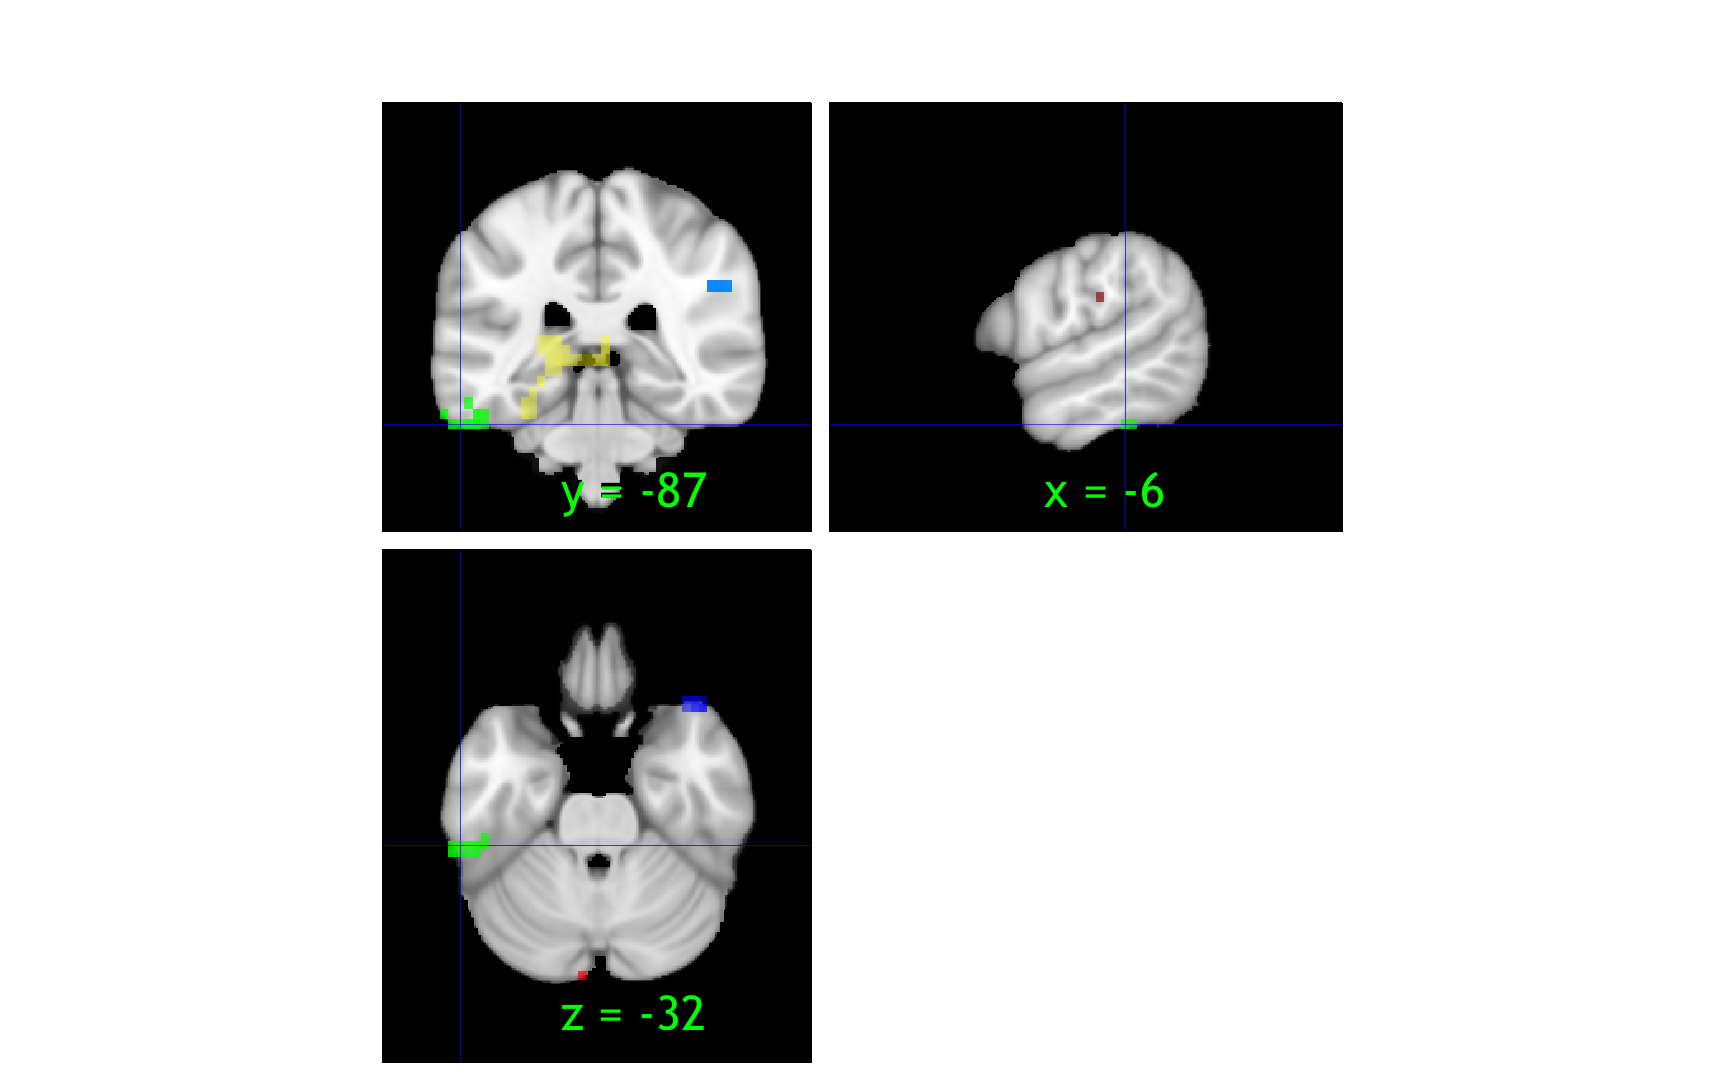

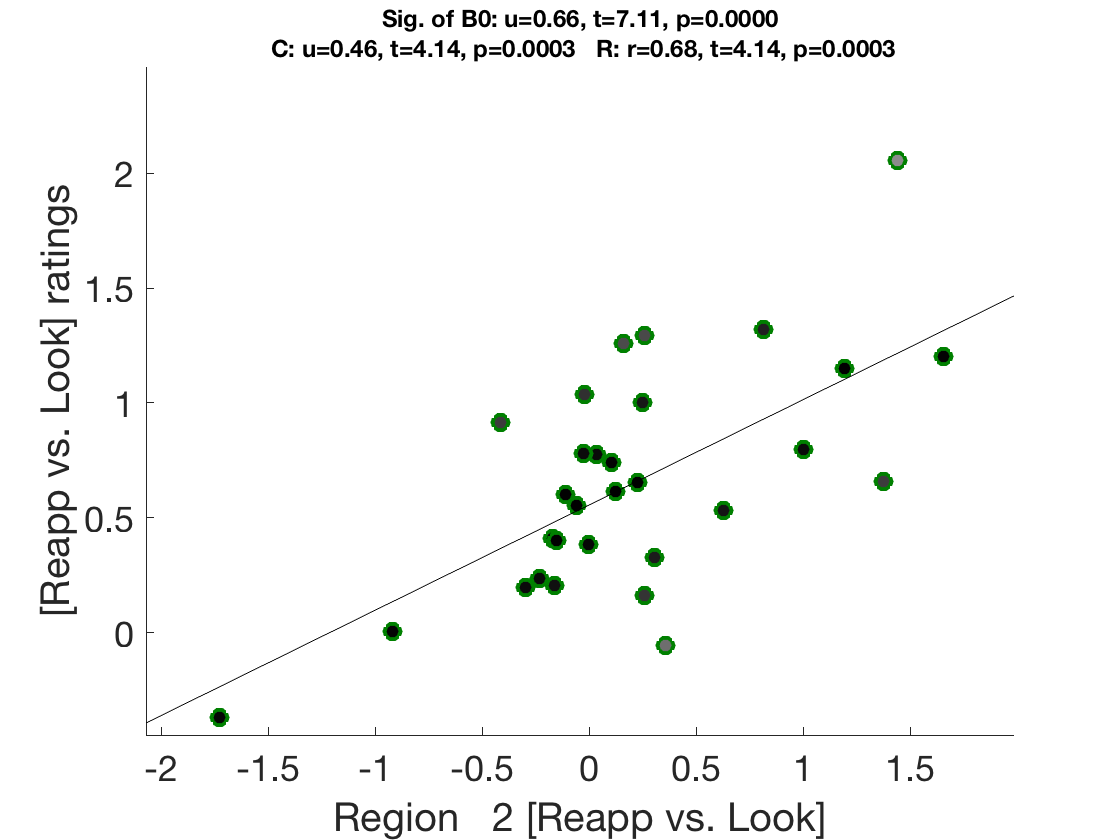


Image   1
Positive effect: 1311 voxels, min p-value: 0.00000000
Negative effect:  67 voxels, min p-value: 0.00002585

Image   2
Positive effect: 279 voxels, min p-value: 0.00000120
Negative effect: 623 voxels, min p-value: 0.00000002


Grouping contiguous voxels: 123 regions


Found surface patch handles - plotting on existing surfaces.
cluster_surf
___________________________________________
	  1 cluster structures entered
  Colors are:
 1  1  0
 Building XYZ coord list
 Building color change function call
 Using existing surface image
 Running color change.
 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],5,'ovlcolor',[0 1 1]);
Main color vertices: 421997 vertices.  selecting: 415101
1311 coords.  selecting: 1311
Running   2 sets of coordinates: 000001002Finished!
___________________________________________
Found surface patch handles - plotting on existing surfaces.
cluster_surf
___________________________________________
	  1 cluster structures entered
  Colors are:
 0  0  1
 Building XYZ coord list
 Building color change function call
 Using existing surface image
 Running color change.
 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],5,'ovlcolor',[0 1 1]);
Main color vertices: 421997 vertices.  selecting: 213031
 67 co

No vTal field for cluster, attempting to create it.
Range of cl is: 0.50001,1. Threshold is :0.25001


No vTal field for cluster, attempting to create it.
Range of cl is: 0.50004,0.98245. Threshold is :0.25002


ans =   handle to deleted Light


Found surface patch handles - plotting on existing surfaces.
cluster_surf
___________________________________________
	  1 cluster structures entered
  Colors are:
 1  1  0
 Building XYZ coord list
 Building color change function call
 Using existing surface image
 Running color change.
 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],5,'ovlcolor',[0 1 1]);
Main color vertices: 864 vertices.  selecting: 864
1311 coords.  selecting:  12
Running   1 sets of coordinates: 000001 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],5,'ovlcolor',[0 1 1]);
Main color vertices: 436 vertices.  selecting: 436
1311 coords.  selecting:  73
Running   1 sets of coordinates: 000001 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],5,'ovlcolor',[0 1 1]);
Main color vertices: 1182 vertices.  selecting: 1182
1311 coords.  selecting:  68
Running   1 sets of coordinates: 000001 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],5,'ovlcolor',[0 1 1]